# **Testskript für das Laubharkprojekt**

Dies ist das "offizielle" Testskript für das Laubharkprojekt. Alle Tests, die durchgeführt werden sollen, werden hier gesammelt. Dadurch sind die Tests zentral an einem Ort verfügbar, und man muss keine wilde Sammlung einzelner Testdateien anlegen...

Dieses Skript soll außerdem dabei helfen, die Duplizierung von Testcode auf ein Minimum zu beschränken - was hoffentlich die Wartung und Erweiterung der Tests in Zukunft start vereinfacht!

Die einzelnen Sektionen im obigen Inhaltsverzeichnis stellen je einen eigene Test, bzw. ein eigenes Testszenario dar.

**Vor der Durchführung irgendwelcher Tests MUSS auf jeden Fall die Sektion "Vorbereitung" ausgeführt werden!**

Das ist notwendig, damit alle Tests über die gleichen Dateipfade verfügen und der Workspace einmal aufgeräumt wird.

Es ist nicht notwendig, alle Berechnungen selbst auszuführen, um die Ergebnisse zu inspizieren. Stattdessen kann auf die bereits berechneten Ergebnisse zurückgegriffen werden, die im Ordner Ergebnisse abgelegt sind. Dort werden sie dann vom testScript selbst erkannt und automatisch geladen, sofern das gewollt ist. Dafür sorgen die '`testScriptUtils.loadTest()`' statements zu Beginn jeder Matlab-Codesektion. Sollen die Tests berechnet werden, anstatt vorherige Ergebnisse zu laden, kann dies mit der Funktion '[testScriptUtils.loadTestSettings()](matlab:help testScriptUtils.loadTestSettings)' eingestellt werden. Dazu sei der Leser auf die entsprechende [Hilfe](file://docs/_build/html/files/code/testing.html?highlight=testscriptutils#Ergebnisse.testScript_tests.testScriptUtils.loadTestSettings) verwiesen.

# Vorbereitung (Wichtig!)

Diese Sektion ist vor der Ausführung anderer Tests einmal auszuführen!

clearvars;
close all;

% Pfade zu MATLAB hinzufuegen
% addpath(genpath("."));
import('lhp.*');
import('lhp.utils.*');
import('lhp.rating.*');
import('lhp.algo.*');

addpath("Ergebnisse/testScript_tests/");



# Tests für die Heuristiken

## Szenario 1: Zusammenhang zwischen maximaler Laub- und maximaler Transportmenge

Mit diesem Test soll untersucht werden, welcher Zusammenhang zwischen der maximalen Laubmenge und der maximalen Transportmenge besteht.

Dabei wird die maximale Laubmenge in bestimmten Schrittgrößen erhöht, und die maximale Laub-Transportmenge ebenfalls in der selben Schrittgröße von 10 bis zu derzeitigen Laubmenge erhöht. Dabei betrachten wir ebenfalls Gärten verschiedener Größen. Der Test betrachtet im Moment die 5 ursprünglichen Heuristiken, lässt sich aber auch mit beliebigen anderen Heuristiken verwenden.

if ~testScriptUtils.loadTest(1, 1)
    
    import('lhp.algo.*');

    algorithms_to_test = [
        DeterministicWrapper.gather("Range", [13, 61, 12, 7], "OptimizeMaxLaub", false), ...
        DeterministicWrapper.gather("Range", [13, 61, 12, 7], "OptimizeMaxLaub", true, ...
            "NameSuffix", "_OPT");
    ];
    
    tm = lhp.utils.TestManager();
    for att = 1:numel(algorithms_to_test)
        tm.addAlgorithm(algorithms_to_test(att));
    end


Hier werden die Größen der zu testenden Gärten definiert. Für jede Gartengröße wir **genau ein** Garten erzeugt und systematisch getestet. Auf diese Weise arbeiten alle Algorithmen für alle Parametervariationen innerhalb einer Gartengröße mit dem selben Garten!

    % USER PARAMETERS
    min_laub = 10;
    max_laub = 30;
    min_trans = 5; %max_trans is determined by current Max_Val (laub) in tests
    max_trans = max_laub;
    % ---------------
    ZE = 15;  % Fix to 15, vary only the columns
    ALL_SP = 10:5:20;
    
    % Teste Zusammenhang zwischen MaxTrans und MaxLade
    % Stelle sicher, dass wir immer die selben Gaerten verwenden!
    for SP = ALL_SP
        G = lhp.Garden.random(ZE, SP);
        data = lhp.ProblemData(ZE, SP, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1, ...
            "MaxLaub", 1, ...   % Wird ueberschrieben
            "MaxLade", 1);      % Wird ueberschrieben

        for maxLaub = min_laub:1:max_laub
            data.Max_Val = maxLaub;

            for maxTrans = min_trans:1:max_trans
                data.Max_Trans = maxTrans;
                info_str = sprintf("Gartengroesse: %d x %d; MaxLaub: %d; MaxTrans: %d", ZE, SP, maxLaub, maxTrans);
                
                tm.addTestCase(data, info_str);
            end
        end
    end
    
    tm.runAllTests();
    
    % After completion store the results so we can load them later.
    % We store all variables that we need in the following evaluation block.
    testScriptUtils.saveTest(1, 1, "tm", "min_laub", "max_laub", "ZE", "ALL_SP", ...
        "algorithms_to_test", "min_trans", "max_trans");
end

Begin running 13104 tests!

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).



Test completion: 100.00 %   (13104 / 13104)
[==============================================================================]


**Der folgende Code erzeugt Plots, die nicht in das LiveSkript eingebettet werden können! Das ist bekannt und Absicht so!**

In den Plots der nicht Laubmengenoptimierten Heuristiken ist zu erkennen, dass die **Ergenisse häufig dann am besten** sind (die niedrigsten Gesamtkosten erzeugen), wenn die **Transportmenge gleich der Laubmenge** ist. Unabhängig davon ist jedoch bei den **laubmengenoptimierten Algorithmen** zu beobachten, dass die Optimierung eine zum Teil **erhebliche Verbesserung** der Ergebnisse hervorbringen kann.

Insbesondere hilft die Optimierung dabei, gute Lösungen unabhängig vom Verhältnis zwischen maximaler Laubmenge pro Feld und maximaler Transportmenge zu erzielen. Dadurch werden die hier untersuchten Heuristiken **unempfindlicher gegen ungünstige Randbedingungen**.

laubs = min_laub:1:max_laub;
num_gardens = numel(ZE) * numel(ALL_SP);

for alg_idx = 1:numel(algorithms_to_test)
    alg_name = algorithms_to_test(alg_idx).get_name();
    % Placeholder for our data.
    alg_data = zeros(numel(laubs), numel(min_trans:1:max_trans), num_gardens);
    
    for my_max_val = 1:numel(laubs)
        [costs, gardens, trans] = tm.extract(...
            alg_name, "K", ...
            "GroupBy", "Garden", ...
            "SortBy", "Max_Trans", ...
            "From", tm.where("Max_Val", "==", laubs(my_max_val)));
        costs = permute(costs, [2, 1, 3]);
        % Extend missing data with NaN
        dummy = NaN(size(costs, 1), ...
            size(alg_data, 2) - size(costs, 2), ...
            size(costs, 3));
        alg_data(my_max_val, :, :) = cat(2, costs, dummy);
    end
    
    figure();
    tg = uitabgroup();
    for g = 1:num_gardens
        thistab = uitab(tg, "Title", sprintf("%d x %d", size(gardens{g})));
        axes("Parent", thistab);
        plt = surf(alg_data(:, :, g));
        title(sprintf("Algorithmus: %s - Gartengroesse: %d x %d", ...
            alg_name, size(gardens{g})));
        % Format x-Axis
        xlabel("Transportmenge");
        xticks(1:numel(min_trans:1:max_trans));
        xticklabels(min_trans:1:max_trans);
        % Format y-Axis
        ylabel("Laubmenge");
        yticks(1:numel(min_laub:1:max_laub));
        yticklabels(min_laub:1:max_laub);
        % Format rest of figure
        zlabel("Absolute Kosten");
        plt.Parent.ZScale = 'log';
        view(120, 30)
        grid("minor");
    end
end

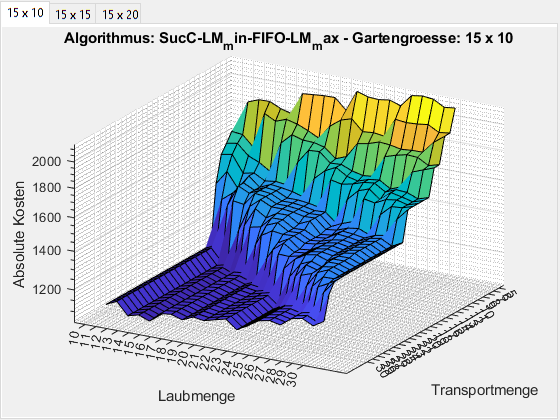

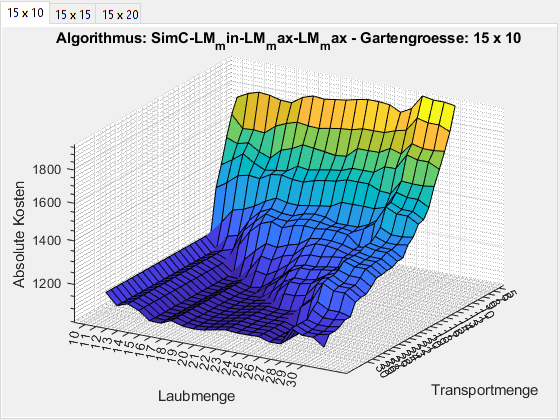

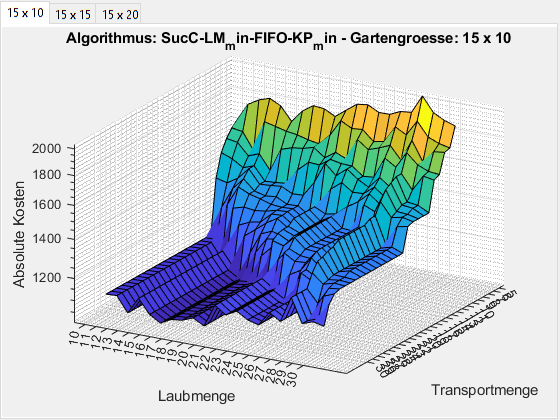

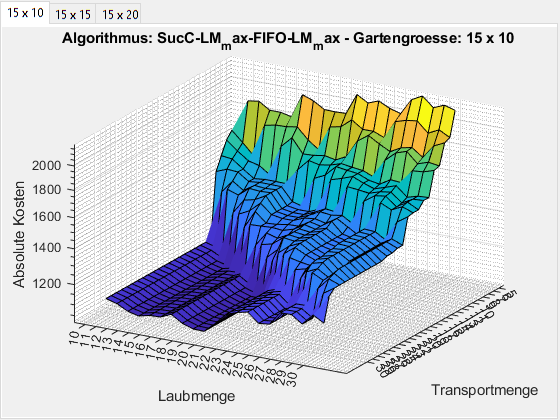

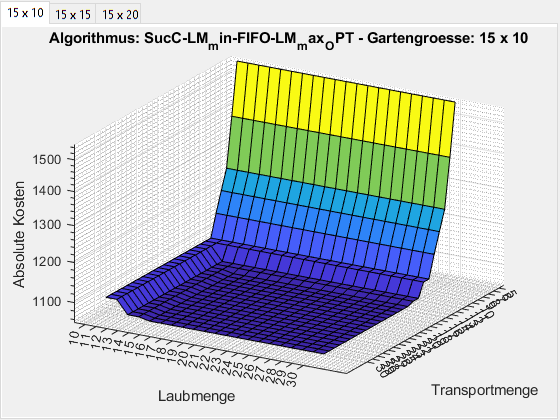

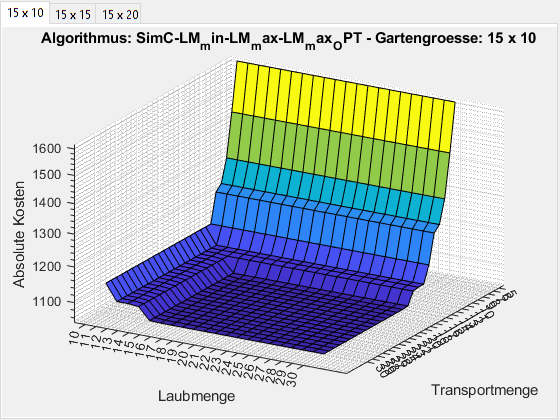

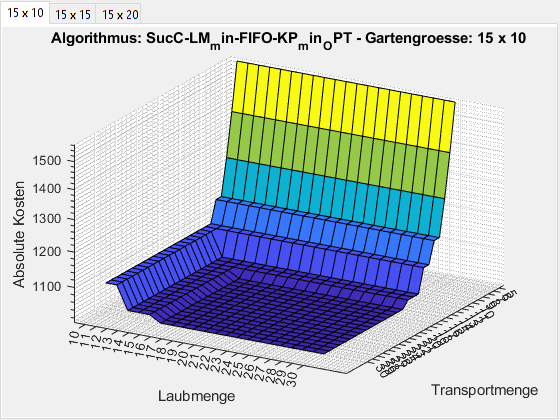

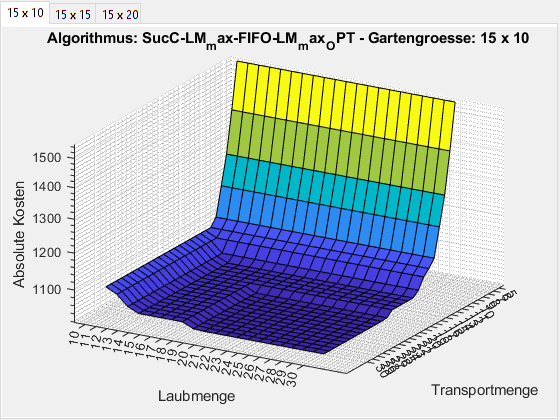

% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.

clearvars;

## Szenario 2: Heuristiken mit und ohne Laubmengenoptimierung

In diesem Test wird untersucht, welche Verbesserung die Optimierung der maximalen Laubmenge bei den Heuristiken bringt. Hermanns Vermutung lautet, dass die Heuristiken damit immernoch schneller sind als die genetischen Algorithmen und dennoch sehr gute Ergebnisse liefern. In diesem Test schauen wir uns aber erst einmal nur an, wie sich die Heuristiken untereinander verhalten, wenn die Laubmenge optimiert wird oder eben nicht.

Wir betrachten Beispielhaft Gärten mit 10x10, 15x15, 20x20 und 30x30 Feldern. In diesem Test wird die maximale Laubmenge pro Feld in einem Interval [1, 3.5 * (maximale Transportmenge)] jeweils um 1 inkrementiert und getestet. Dieses Testszenario wurde bewusst überspitzt gewählt, auch um zu zeigen, dass die Gesamtkosten der Heuristiken in einigen Fällen dann lokal minimal werden, wenn die maximale Laubmenge nahe einem ganzzahligen vielfachen der Transportmenge ist. Diese Aussage ist jedoch nicht für alle Heuristiken wahr. Im allgemeinen lässt sich sagen, dass in den untersuchten Szenarien eine Erhöhung der maximalen Laubmenge über die Transportmenge zu einer Verschlechterung der Ergebnisse führt (sofern keine Laubmengeoptimierung durchgeführt wird).

In diesem Test sieht man vor allem, dass die Laubmengeoptimierten Algorithmen ab einem bestimmten Punkt (*Und grade bei Zickzack liegt der vor der maximalen Transportmenge*) ihr Optimum erreicht haben und weitere Lauberhöhungen schlicht ignorieren.

if ~testScriptUtils.loadTest(1, 2)

    % Definition der zu testenden Algorithmen
    algorithms_to_test = [...
        lhp.algo.DeterministicWrapper.gather(...
            "OptimizeMaxLaub", false, "Range", [13, 61, 12, 7]), ...
        lhp.algo.DeterministicWrapper.gather(...
            "OptimizeMaxLaub", true , "Range", [13, 61, 12, 7], "NameSuffix", "_OPT") ...
    ];    
    
    tm = lhp.utils.TestManager();
    for att = algorithms_to_test
        tm.addAlgorithm(att);
    end
    
    %% Define the tests.
    % Define garden sizes
    garden_sizes = [10, 15, 20, 30];
    max_laubs = 1:1:70;
    
    % Stelle sicher, dass wir immer die selben Gaerten verwenden!
    for gs = garden_sizes
        G = lhp.Garden.random(gs, gs);
        data = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1, ...
            "MaxLaub", 1, ...   % Wird ueberschrieben
            "MaxLade", 20);
        
        for maxLaub = max_laubs
            data.Max_Val = maxLaub;
            info_str = sprintf("Garten %d x %d; MaxLaub: %d", gs, gs, maxLaub);
            tm.addTestCase(data, info_str);
        end
    end
        
    %% Fuehre alle Tests durch.
    tm.runAllTests();
    
    % Store results so we can use them later.
    testScriptUtils.saveTest(1, 2, "algorithms_to_test", "garden_sizes", ...
        "max_laubs", "tm");
end

Begin running 2240 tests!




Test completion: 100.00 %   ( 2240 /  2240)
[==============================================================================]


Beobachtungen bei den Ergebnissen:

- Der **Zickzack Algorithmus** scheint sehr von der Laubmengenoptimierung zu profitieren, da er damit oft schon vor erreichen der maximalen Transportmenge ein Optimum findet.

- Die **optimierte Version des Zickzack Algorithmus** läuft bei 50+ Iterationen immernoch schneller als die anderen Heuristiken bei einer einzigen Iteration.

- Eine Erhöhung der maximalen Laubmenge über die maximale Transportmenge hat keinen Effekt auf die optimierten Algorithmen (Weil die Kosten dann weiter steigen).

- Ab einer Erhöhung der maximalen Laubmenge über die erlaubte Transportmenge **stagnieren die Ausführungszeiten der Algorithmen**. Die Ursache für dieses Verhalten ist unbekannt.

- Es ist ein näherungsweise **linearer Zusammenhang** zwischen der **Ausführungszeit** und der **maximalen Laubmenge** bei den laubmengenoptimierten Heuristiken beobachtbar, bis zu einer Laubmenge gleich der Transportmenge.

line_colors = ["blue", "red", "yellow", "green", "magenta"];

my_var = ["K", "time"];
ylabels = ["Kosten", "Ausfuehrungszeit / s"];

for var_idx = 1:2
    color_ctr = 0;
    figure();
    for alg = algorithms_to_test
        color_ctr = color_ctr + 1;
        [data, grouped_by, sorted_by] = tm.extract(alg.get_name(), my_var(var_idx), "GroupBy", "Garden", "SortBy", "Max_Val");
        
        for depth = 1:size(data, 3)
            subplot(2, 2, depth);
            alg_name = alg.get_name("Latex");
            hold on;
            linestyle = "-";
            linecolor = line_colors(mod(color_ctr, 5) + 1);
            % Use dashed lines for optimized algorithms
            if regexpi(alg_name, "{OPT}$")
                linestyle = "--";
            end
            plot(data(:, :, depth), ...
                "DisplayName", alg_name, ...
                "Color", linecolor, ...
                "LineStyle", linestyle, ...
                "LineWidth", 2);
            title(sprintf("Garten: %d x %d (Index %d)", ...
                size(grouped_by{depth}, 1), ...
                size(grouped_by{depth}, 2), ...
                depth));
            xlabel("Maximale Laubmenge");
            ylabel(ylabels(var_idx));
            grid("on");
            legend('Location', 'NorthWest');
        end
    end
end


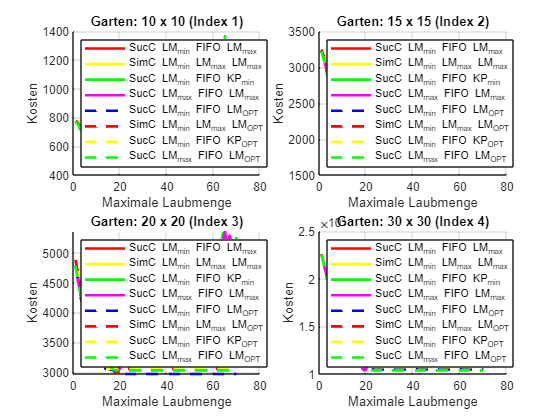

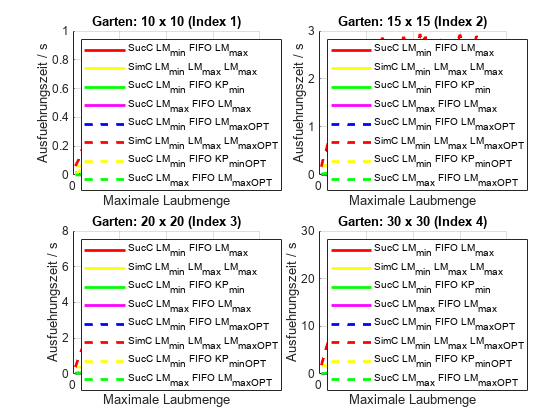

% Nur fuer Batch-Modus:

% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

## Szenario 3: Vergleich aller Heuristiken

Dieser Test soll alle verfuegbaren Heuristiken mit einander vergleichen. In einer groß angelegten Version dieses Tests habe ich 87 Heuristiken insgesamt 420 verschiedene Gärten lösen lassen. Die Ergebnisse sahen wie folgt aus:

Demnach haben die besten 5 Heuristiken in der Datei `heuristics.txt` die Indizes (vom besten zum schlechtesten):


$$\{ 13, 1, 61, 12, 7 \}$$


if ~testScriptUtils.loadTest(1, 3)
    algorithms_to_test = lhp.algo.DeterministicWrapper.gather("OptimizeMaxLaub", false);
    
    tm = lhp.utils.TestManager();
    for att = algorithms_to_test
        tm.addAlgorithm(att);
    end
    
    %% Define the tests.
    % Define garden sizes
    garden_sizes = 10:1:30;
    rep_garden_sizes = repmat(garden_sizes, 1, 20);
    
    % Teste Zusammenhang zwischen MaxTrans und MaxLade
    % Stelle sicher, dass wir immer die selben Gaerten verwenden!
    for gs = rep_garden_sizes
        G = lhp.Garden.random(gs, gs);
        data = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1, ...
            "MaxLaub", 20, ...
            "MaxLade", 20);
        
        info_str = sprintf("Garten %d x %d;", gs, gs);
        tm.addTestCase(data, info_str);
    end
    
    %% Run the tests
    tm.runAllTests();
    
    testScriptUtils.saveTest(1, 3, "algorithms_to_test", ...
        "tm", "garden_sizes", "rep_garden_sizes");
end


%% Evaluate stuff
table = tm.get_results();
table = table(:, 4:end);

Begin running 34860 tests!




Test completion: 100.00 %   (34860 / 34860)
[==============================================================================]


alg_names = [table.Properties.VariableNames];

for idx = 1:size(table, 1)
    subtable = table(idx, :);
    table_results = subtable{1, :};
    costs(idx, :) = [cellfun(@(cell) (cell.K), table_results)]; %#ok
end


Die hier gezeigte Abbildung stellt für die ersten 21 erstellen Gärten dar, welche Kosten die Heuristiken jeweils errechnet haben. Insbesondere bei kleinen Gartengrößen liegen die Kosten nah bei einander. Es fällt auf, dass **charakteristische "Knicke"** im Kostenverlauf über der Gartengröße **bei allen Algorithmen** vorhanden sind. Somit scheinen topologische Gegebenheiten des Gartens alle Algorithmen relativ gesehen in ähnlichem Ausmaß zu betreffen.

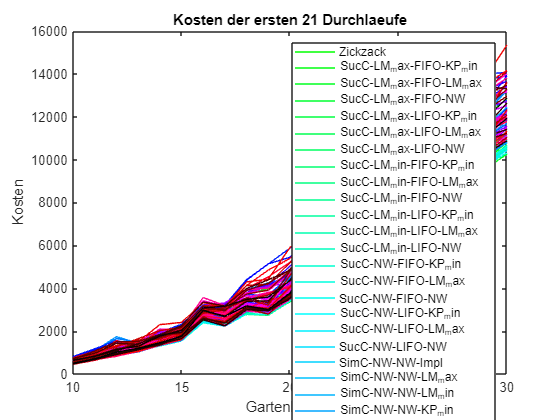

% Der Befehl "varycolor" kommt aus dem Matlab FileExchange.
% Er erzeugt eine gegebene Anzahl an verschiedenen farben.
plot_colors = varycolor(numel(alg_names));
figure();
for tmp = 1:numel(alg_names)
    plot(garden_sizes, costs(1:numel(garden_sizes), tmp), ...
        "DisplayName", alg_names{tmp}, ...
        "Color", plot_colors(tmp, :));
    hold on;
end
title(sprintf("Kosten der ersten %d Durchlaeufe", numel(garden_sizes)));
xlabel("Gartenlaenge");
ylabel("Kosten");
legend();

% Determine which algorithm was best
bins = zeros(size(alg_names));
for tmp = 1:size(costs, 1)
    [~, idx] = min(costs(tmp, :), [], 2);    

    bins(idx) = bins(idx) + 1;
end

% Print scores in a table
fprintf("\n\n\n");
longest_str = max(cellfun(@(cell) (size(cell, 2)), alg_names));
fprintf("  %*s | %s \n", longest_str, "Algorithmenname", "# Beste Loesungen");
fprintf(" -%s-+-%s- \n", repmat('-', 1, longest_str), "----");
[~, sortvec] = sort(bins, "descend");

for tmp = sortvec
    if (bins(tmp) > 0)

            Algorithmenname | # Beste Loesungen 


        fprintf("  %*s | %4d \n", longest_str, alg_names{tmp}, bins(tmp));

 ---------------------------+------ 


    end
end


    SucC-LM_max-FIFO-LM_max |  110 
        SucC-NW-FIFO-LM_max |  104 
    SucC-LM_min-FIFO-LM_max |   50 
    SucC-LM_min-FIFO-KP_min |   35 
    SucC-LM_max-LIFO-LM_max |   17 
  SimC-LM_min-LM_max-LM_max |   17 
    SucC-LM_min-LIFO-LM_max |   11 
        SucC-NW-LIFO-LM_max |   11 
      SimC-LM_min-NW-LM_max |   10 
        SucC-NW-FIFO-KP_min |    9 
          SimC-NW-NW-LM_max |    8 
      SimC-NW-LM_max-LM_max |    8 
  SimC-LM_min-KP_min-LM_max |    8 
  SimC-KP_min-KP_min-LM_max |    6 
  SimC-LM_min-LM_min-LM_max |    5 
    SucC-LM_min-LIFO-KP_min |    3 
        SucC-LM_min-FIFO-NW |    2 
            SucC-NW-FIFO-NW |    1 
      SimC-NW-KP_min-LM_max |    1 
  SimC-LM_max-LM_min-LM_max |    1 
  SimC-LM_min-KP_min-KP_min |    1 
      SimC-KP_min-NW-LM_max |    1 
  SimC-KP_min-LM_min-LM_max |    1 


Die oben dargestellten Zahlen lassen sich in das Verhältnis zur Gesamtzahl an Gärten setzen. Damit erhält man die folgenden Anteile, in denen die besten 5 Heuristiken jeweils das beste Ergebnis lieferten:

- SucC-LMmin-FIFO-LMmax: 26.67 %

- Cluster-MAX: 19.05 %

- SimC-LMmin-LMmax-LMmax: 14.76 %

- SucC-LMmin-FIFO-KPmin: 12.14 %

- SucC-LMmax-FIFO-LMmax: 8.09 %

Zusammen liefern diese 5 Algorithmen in 80.71 % der Fälle das beste Ergebnis aus allen 87 Heuristiken.

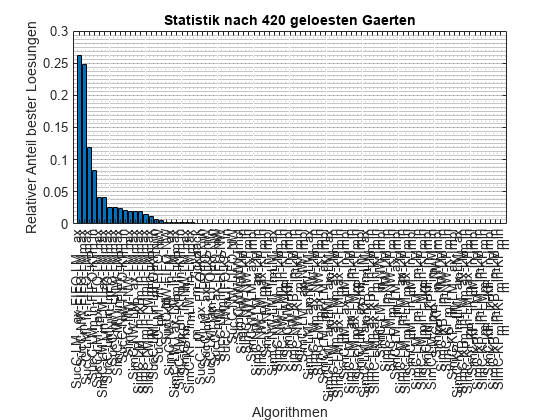

[sorted_bins, sort_vec] = sort(bins, "descend");
sorted_names = alg_names(sort_vec);
sorted_names = cellfun(@(cell) (string(cell)), sorted_names);

rel_bins = sorted_bins ./ sum(sorted_bins);
figure();
bar(1:numel(bins), rel_bins);
title(sprintf("Statistik nach %d geloesten Gaerten", size(table, 1)));
xlabel("Algorithmen");
ylabel("Relativer Anteil bester Loesungen");
grid("minor");
xticks(1:numel(bins));
xticklabels(sorted_names);
xtickangle(90);


% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

## Szenario 4: Test der Hubzentrierung als Nachbesserungsmethode

In diesem Test wird untersucht, ob die implementierten Heuristiken in der Hubzentrierung (hz.m) zu einer Verbesserung der durch die Heuristiken ermittelten Ergebnisse führen können. Dazu wird mit allen Heuristiken für mehrere Gärten verschiedener Größe eine Lösung erzeugt, und diese anschließend mit jeder Hubzentrierungs-Methode nachbearbeitet. Die Ergebnisse werden am Ende verglichen.

if ~testScriptUtils.loadTest(1, 4)

    % Definition der zu testenden Algorithmen
    heuristics = lhp.algo.DeterministicWrapper.gather("OptimizeMaxLaub", true, "NameSuffix", "_OPT");
    
    tm = lhp.utils.TestManager();
    for hidx = 1:numel(heuristics)
        tm.addAlgorithm(heuristics(hidx));
    end
    
    %% Define the tests.
    % Define garden sizes
    garden_sizes = [10, 25, 50];
    % Number of repetitions/tests per garden size. For statistical purposes.
    num_repetitions = 5;
    
    % Standard Testszenario.
    for gs = garden_sizes
        for nr = 1:num_repetitions
            G = lhp.Garden.random(gs, gs);
            data = lhp.ProblemData(gs, gs, ...
                "Garten", G, ...
                "HarkParam", 1, ...
                "WegeParam", 1, ...
                "TransParam", 1, ...
                "MaxLaub", 20, ...
                "MaxLade", 20);
    
            info_str = sprintf("Run %d; Garden %d x %d", nr, gs, gs);
            tm.addTestCase(data, info_str);
        end
    end
    
    clearvars("gs", "nr", "G", "data", "info_str");
        
    % Run the tests
    tm.runAllTests();

    % Variable definitions for following sections
    methods = ["MaxLaub", "MinLaub", "Median", "MinKompost", "SmallestIndex"];
    
    NUM_GARDENS = numel(garden_sizes);
    NUM_ALGS = numel(heuristics);
    NUM_TESTS = NUM_GARDENS * num_repetitions;
    % Offset in the results table, where the actual results are stored.
    TABLE_OFFSET = 3;
    
    results = tm.get_results();
    
    opt_alg = struct();
    % Indexes by which we find the optimized algorithms in the TM
    opt_alg.("Indexes") = 1:NUM_ALGS;
    % Cell array for the successor functions. First dimension (rows) equals the
    % method for post-optimization, Second dimension (cols) equals the specific
    % algorithm we inspect. The third dimension is for the different test cases.
    % We add +1 in the first dimension because we're interested in the basic
    % solutions, too, for comparison.
    opt_alg.("Successors") = cell(1, NUM_ALGS, NUM_TESTS);
    % Raw costs of all the tests we make
    opt_alg.("Costs") = zeros(size(opt_alg.("Successors")));
    % For the improvements of each post-optimization over the base solution
    opt_alg.("Improvements") = zeros(size(opt_alg.("Successors")));
    % Names of the algorithms for plots
    opt_alg.("Names") = [arrayfun(@(heur) heur.get_name("Latex"), heuristics)]; %#ok

    % We do the post-processing here and calculate all costs.
    % This takes a lot of time!
    progbar = lhp.utils.ProgressBar(...                                                                
        "WindowWidth", 80, ...                                                               
        "BarStyle", "=", ...                                                                 
        "WidestNumber", 5, ...                                                               
        "UpdateString", "Post-processing in progress...", ...                                               
        "UpdateEvery", 2);
    
    for alg_idx = opt_alg.("Indexes")
        progbar.update(alg_idx, numel(opt_alg.("Indexes")));
        for test_idx = 1:NUM_TESTS
            orig_suc = results{test_idx, alg_idx + TABLE_OFFSET}{1}.s;
            opt_alg.("Successors"){1, alg_idx, test_idx} = orig_suc;
                    
            orig_cost = results{test_idx, alg_idx + TABLE_OFFSET}{1}.K;
            opt_alg.("Costs")(1, alg_idx, test_idx) = orig_cost;
                    
            pdata = results.ProblemData{test_idx};
            
            for met_idx = 1:numel(methods)
                s_new = lhp.utils.hz(pdata, orig_suc, methods(met_idx));
                opt_alg.("Successors"){1 + met_idx, alg_idx, test_idx} = s_new;
                
                [~, ~, ~, K] = lhp.rating.get_costs(s_new, pdata);
                opt_alg.("Costs")(1 + met_idx, alg_idx, test_idx) = K;
                
                opt_alg.("Improvements")(1 + met_idx, alg_idx, test_idx) = ...
                    ((K - orig_cost) / orig_cost) * 100;
            end
        end
    end
    
    % Cleanup after ourselves.
    clearvars("progbar", "alg_idx", "test_idx", "orig_suc", "orig_cost", ...
        "pdata", "met_idx", "s_new", "K", "TABLE_OFFSET", "NUM_ALGS", ...
        "NUM_TESTS", "results");
    
    testScriptUtils.saveTest(1, 4, "NUM_GARDENS", "garden_sizes", ...
        "opt_alg", "num_repetitions", "methods");
end


Begin running 1245 tests!




Test completion: 100.00 %   ( 1245 /  1245)
[==============================================================================]


Post-processing in progress...: 100.00 %   (   83 /    83)
[==============================================================================]


Hier werden die Plots erzeugt. Bei der Interpretation der Grafik gilt es, folgendes zu beachten:

- Auf der x-Achse sind die 87 Heuristiken aufgetragen 

- Auf der y-Achse sind die Hubzentrierungsmethoden aufgetragen 

- Auf der z-Achse ist die Verbesserung einer Hubzentrierungsmethode gegenüber der "Standardlösung" ("None") in Prozent zu sehen 

- Die Größe der Marker gibt Aufschluss über die Gesamtgüte der Lösung: Große Marker haben geringere Kosten, kleine Marker entsprechend höhere Kosten 

- Die Farbe der Marker gibt Aufschluss über die erzielte Verbesserung. Grüne Marker konnten die Gesamtkosten reduzieren, rote Marker haben die Gesamtkosten verschlechtert. Siehe Farbbalken rechts im Bild.

Eine genauere Interpretation der Ergebnisse in Textform wird weiter unten vom Skript selbst vorgenommen. Zum Zeitpunkt der Untersuchung war die Methode Median die erfolgreichste Hubzentrierung und führte im Schnitt zu einer Verbesserung der errechneten Lösungen von 9.87 % der Gesamtkosten. Dabei ist zu beachten, dass diese Verbesserung über alle betrachteten Algorithmen und Gärten erzielt wurde. Eine Betrachtung der durchschnittlichen Verbesserung pro Algorithmus und Garten erfolgt an dieser Stelle nicht, kann aber bei Interesse vom Nutzer selbst implementiert werden.

Mit den durchschnittlichen Verbesserungen der 50x50 Felder großen Gärten ergibt sich beispielsweise bei der Median Methode für die 5 besten Heuristiken (nach Test 1.2):

Im allgemeinen lässt sich festhalten: 

- Von den implementierten Hubzentrierungsmethoden liefern über alle Gärten und Heuristiken hinweg nur die **"Median" und "MaxLaub"** Methode **konsistente Verbesserungen** der Gesamtkosten.

- Die **beste Hubzentrierungsmethode** (gemessen an der Verbesserung in Relation zu den Gesamtkosten) ist die **"Median"** Methode.

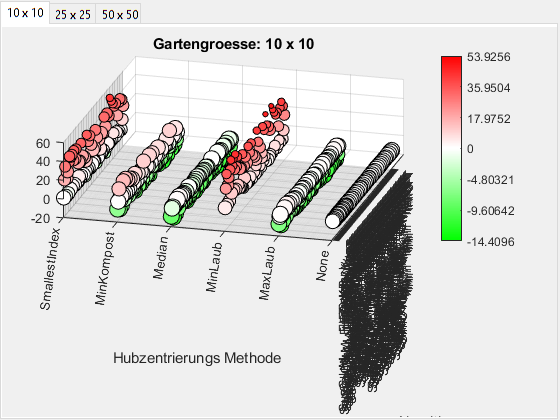

%% Do the plots
fig = figure();
tg = uitabgroup();
for g = 1:NUM_GARDENS
    thistab = uitab(tg, "Title", sprintf("%d x %d", ...
            garden_sizes(g), garden_sizes(g)));
    axes("Parent", thistab);
    
    mean_improvement = mean(opt_alg.("Improvements")(:, :, ...
            ((g-1)*num_repetitions + 1):(g*num_repetitions)), 3);
    % Scatter expects to get multiple vectors of same length.
    % We must chop up the matrix we generated above as well as the X/Y indexes.
    % We chop it up column-wise.
    X_mat = repmat(opt_alg.Indexes, size(mean_improvement, 1), 1);
    Y_mat = ones(size(mean_improvement)) .* (1:size(mean_improvement, 1))';
    x = reshape(X_mat, [], 1);
    y = reshape(Y_mat, [], 1);
    z = reshape(mean_improvement, [], 1);
    % Marker sizes represent how "good" (lowest cost) the solution was. Bigger
    % markers mean lower costs.
    marker_min_size = 16;
    marker_max_size = 160;
    my_costs = mean(opt_alg.("Costs")(:, :, ...
            ((g-1)*num_repetitions + 1):(g*num_repetitions)), 3);
    normalized_costs = 1 - rescale(my_costs);
    s =  reshape(normalized_costs, [], 1) * ...
        (marker_max_size - marker_min_size) + marker_min_size;
    % Marker colors represent the improvement of a solution. A solution improved
    % if the total cost after post-processing was lower, i.e. the cost reduction
    % is negative. Negative values are green, positive values are red.
    color_good = [0, 1, 0];
    color_bad  = [1, 0, 0];
    c = zeros(size(z, 1), 3);
    z_good = 0.0 + rescale(z(z < 0), 0.1, 1);
    z_bad  = 1.1 - rescale(z(z > 0), 0.1, 1);
    c(z < 0, :) = c(z < 0, :) + (z_good * (1 - color_good)) + color_good;
    c(z > 0, :) = c(z > 0, :) + (z_bad * (1 - color_bad) + color_bad);
    c(z == 0, :) = c(z == 0, :) + [1, 1, 1];
    % Plot the data now
    % We add a marker edge because otherwise the pale points are hard to see.
    plt = scatter3(x, y, z, s, c, 'filled', ...
            'MarkerEdgeColor', 'k');

    % Assemble the colorbar that sits next to the plot
    colormap_size = [256, 3];
    cmp = ones(colormap_size);
    cmp(1:128, :) = (linspace(0, 1, 128)' .* (1 - color_good)) + color_good;
    cmp(130:256, :) = (linspace(1, 0, 127)' .* (1 - color_bad)) + color_bad;
    cb = colorbar('Ticks', linspace(0, 1, 7), ...
        'TickLabels', [linspace(min(z), 0, 4), linspace(max(z)/3, max(z), 3)]);
    ax = gca();
    ax.Colormap = cmp;

    % Add plot title
    title(sprintf("Gartengroesse: %d x %d", ...
            garden_sizes(g), garden_sizes(g)));
    % Format x-Axis
    xlabel("Algorithmus");
    xticks(1:numel(opt_alg.Names));
    xticklabels(opt_alg.Names);
    xtickangle(90);
    % Format y-Axis
    ylabel("Hubzentrierungs Methode");
    yticks(1:numel(methods)+1);
    yticklabels(["None", methods]);
    % Format rest of figure
    plt.DataTipTemplate.DataTipRows(1).Label = "Algorithmus";
    plt.DataTipTemplate.DataTipRows(1).Value = reshape(...
        repmat(opt_alg.Names, size(mean_improvement, 1), 1), [], 1);
    plt.DataTipTemplate.DataTipRows(2).Label = "Hubzentrierung";
    plt.DataTipTemplate.DataTipRows(2).Value = reshape(...
        repmat(["None", methods]', 1, size(mean_improvement, 2)), [], 1);
    plt.DataTipTemplate.DataTipRows(3).Label = "(Avg.) Verbesserung";
    row = dataTipTextRow("(Avg.) Kosten", opt_alg.("Costs"));
    plt.DataTipTemplate.DataTipRows(end + 1) = row;
    
    % Adapt view so we look at the plot from above.
    view(-75, 50);
    % Alternative view for better comparison
    %view(-0.1, 80);

end

% Cleanup after ourselves
% We leave:
%   - fig: The handle to the figure we create
%   - mean_improvement: The calculated average improvement per HZ method for
%       the last garden inspected. If you need it for all gardens, calculate
%       it as seen in the code above.
clearvars("tg", "g", "thistab", "X_mat", "Y_mat", "x", "y", "z", ...
    "marker_min_size", "marker_max_size", "my_costs", "normalized_costs", ...
    "s", "color_good", "color_bad", "c", "z_good", "z_bad", "plt", "cmp", ...
    "cb", "ax", "row", "colormap_size");


Hier folgt eine textuelle Interpretation der Ergebnisse.

%% Textual Interpretation
cost_mat = opt_alg.Costs;
num_tests_per_hz = numel(cost_mat(1, :, :));
all_methods = ["None", methods];
[~, method_best_solutions] = min(cost_mat, [], 1);

fprintf(...
"\n\n" + ...
" Interpretation of the Results: \n" + ...
" ============================== \n" + ...



 Interpretation of the Results: 
 - Total Tests per HZ method: 1245 


" - Total Tests per HZ method: %d \n", num_tests_per_hz);
fprintf(...

 - Best scores per HZ method: 


" - Best scores per HZ method: \n");
for mthd_idx = 1:numel(all_methods)
    fprintf(...
"      + %-15s: %5d (%6.2f %%) \n", all_methods(mthd_idx), ...
    sum(method_best_solutions == mthd_idx, 'all'), ...
    sum(method_best_solutions == mthd_idx, 'all') * 100 / num_tests_per_hz);

      + None           :    44 (  3.53 %) 
      + MaxLaub        :    65 (  5.22 %) 
      + MinLaub        :     0 (  0.00 %) 
      + Median         :  1080 ( 86.75 %) 
      + MinKompost     :    55 (  4.42 %) 
      + SmallestIndex  :     1 (  0.08 %) 


end
% Specific interpretation
fprintf(...

 - Average improvement over default solution per HZ method: 


" - Average improvement over default solution per HZ method: \n");
for mthd_idx = 2:numel(all_methods)
    fprintf(...
"      + %-15s: %+7.3f %% \n", all_methods(mthd_idx), ...
    mean((opt_alg.Costs(mthd_idx, :, :) - opt_alg.Costs(1, :, :)) ./ ...
    (opt_alg.Costs(1, :, :)), 'all') * 100);

      + MaxLaub        :  -5.509 % 
      + MinLaub        : +13.684 % 
      + Median         :  -8.078 % 
      + MinKompost     :  -0.957 % 
      + SmallestIndex  :  +7.274 % 


end
% Specific interpretation of best algorithm
[~, best_method] = max(histcounts(method_best_solutions));
% All tests in which the best method was worse than the original solution
was_worse = cost_mat(best_method, :, :) > cost_mat(1, :, :);
fprintf(...
" - The best algorithm (%s) achieved results worse than the \n" + ...
"   default solution in %d cases. \n" + ...
"      - In these cases the average deterioriation was %+5.2f %% \n" + ...
"        of the total cost \n", ...
    all_methods(best_method), ...
    sum(was_worse, 'all'), ...
    mean((cost_mat(best_method, was_worse) - cost_mat(1, was_worse)) * 100 ./ ...

 - The best algorithm (Median) achieved results worse than the 
   default solution in 59 cases. 
      - In these cases the average deterioriation was +1.30 % 
        of the total cost 


        cost_mat(1, was_worse), 'all'));
    
% Cleanup after ourselves.
clearvars("cost_mat", "num_tests_per_hz", "all_methods", ...
    "method_best_solutions", "mthd_idx", "best_method", "was_worse")


% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

## Szenario 5: Optimaler Zeitpunkt der Hubeliminierung

In diesem Test wird untersucht, ob eine Eliminierung leerer Hubs idealerweise vor der Durchführung nachgelagerter Schritte wie z.B. der Hubzentrierung, oder nachher erfolgen sollte.

if ~testScriptUtils.loadTest(1, 5)
    
    garden_sizes = [18, 25, 35, 50];
    gardens = cell.empty(0, numel(garden_sizes));
    maxTransports = 25;
    maxLaubs = maxTransports:-1:1;
    
    tm = lhp.utils.TestManager();
    
    heuristics = lhp.algo.DeterministicWrapper.gather(...
        "StoreResults", false, ...
        "OptimizeMaxLaub", false, ...
        "Range", [13, 16, 19, 12, 7, 29, 49, 41, 45, 61, 77]);
    
    for hidx = 1:numel(heuristics)
        tm.addAlgorithm(heuristics(hidx));
    end
    
    for gs_idx = 1:numel(garden_sizes)
        gs = garden_sizes(gs_idx);
        G = lhp.Garden.random(gs, gs);
        % For internal bookkeeping
        gardens{gs_idx} = G;
        
        pdata = lhp.ProblemData(gs, gs, "Garten", G);
        
        for mT = maxTransports
            pdata.Max_Trans = mT;
            for mL = maxLaubs
                pdata.Max_Val = mL;
                
                tm.addTestCase(pdata, ...
                    sprintf("MaxLaub: %d; MaxTrans: %d; GardenSize: %d", ...
                    mL, mT, gs));
            end
        end
    end
    
    tm.runAllTests();

    % For the progress bar
    iter_idx = 0;
    % All algorithms that were tested for
    algorithms = tm.get_algorithms();
    % tests to perform
    % We test all HZ methods to see if any surprise us in unexpected ways
    hz_methods = ["Median", "MinKompost", "SmallestIndex", "MinLaub", "MaxLaub"];
    % Descriptions of the tests so we know where we are, SZH == "skip zero hubs"
    TestDesc = ["None", "SZH-only", ""];
    
    for hm_idx = 1:numel(hz_methods)
        TestDesc = [TestDesc; ...
            [sprintf("HZ-%s", hz_methods(hm_idx)), ...
             sprintf("SZH-before-HZ-%s", hz_methods(hm_idx)), ...
             sprintf("SZH-after-HZ-%s", hz_methods(hm_idx))]]; %#ok
    end
    TestDesc = reshape(TestDesc', [], 1)';
    % Remove empty entry
    TestDesc(TestDesc == "") = [];
    
    % This is the central data structure. It's organized as a cell matrix that
    % contains regular numeric matrices in each cell, like detailed below
    %
    %
    %                A l g o r i t h m s
    %         .------------------------------. 
    %     /
    %     |   +----------------+ M
    %     |   |                | a
    %  G  |   |                | x
    %  a  |   |                | L
    %  r  |   |                | a
    %  d  |   |                | u
    %  e  |   +----------------+ b
    %  n  |    Test Description
    %  s  |
    %     |   +---+ +---+
    %     |   |   | |   |  . . .
    %     \   +---+ +---+
    cost_matrix = cell(numel(gardens), numel(algorithms));
    placeholder = zeros(numel(maxLaubs), numel(TestDesc));
    
    % Preallocate space
    for cm_idx = 1:numel(cost_matrix)
        cost_matrix{cm_idx} = placeholder;
    end
    
    % Fill in known data (without HZ or SZH)
    test = (TestDesc == "None");
    
    % So we know where we are in the processing
    progbar_max_iter = numel(maxLaubs) * numel(cost_matrix);
    progbar = lhp.utils.ProgressBar(...                                                                
        "WindowWidth", 80, ...                                                               
        "BarStyle", "=", ...                                                                 
        "WidestNumber", 5, ...                                                               
        "UpdateString", "Post-processing in progress...", ...                                               
        "UpdateEvery", 2);
    
    % Iterate over the results table
    results = tm.get_results();
    for alg_idx = 1:numel(algorithms)
        cur_alg = algorithms{alg_idx};
        cur_tests = results.(cur_alg.get_name());
        % Algorithm index into the cost_matrix
        cm_alg_idx = alg_idx;
        
        for res_idx = 1:numel(cur_tests)
            
            cur_pdata = results.ProblemData{res_idx};
            cur_garden = cur_pdata.Garden;
            cur_result = cur_tests{res_idx};
            cur_maxlaub = cur_pdata.Max_Val;
            cur_s = cur_result.s;
            
            % Garden index into the cost_matrix
            cm_garden_idx = (cellfun(@numel, gardens) == numel(cur_garden));
            % MaxLaub index into the cost matrix
            cm_maxlaub_idx = (maxLaubs == cur_maxlaub);
            % Current cost matrix submatrix
            cm_submatrix = cost_matrix{cm_garden_idx, cm_alg_idx};
            
            iter_idx = iter_idx + 1;
            progbar.update(iter_idx, progbar_max_iter);
            
            parfor td_idx = 1:numel(TestDesc)
                cur_td = TestDesc(td_idx);
                s = []; %#ok
                
                switch (cur_td)
                    case "None"
                        s = cur_s;
                    case "HZ-Median"
                        s = lhp.utils.hz(cur_pdata, cur_s, "Median");
                    case "HZ-MinKompost"
                        s = lhp.utils.hz(cur_pdata, cur_s, "MinKompost");
                    case "HZ-SmallestIndex"
                        s = lhp.utils.hz(cur_pdata, cur_s, "SmallestIndex");
                    case "HZ-MinLaub"
                        s = lhp.utils.hz(cur_pdata, cur_s, "MinLaub");
                    case "HZ-MaxLaub"
                        s = lhp.utils.hz(cur_pdata, cur_s, "MaxLaub");
                    case "SZH-only"
                        s = lhp.utils.skip_zero_hubs(cur_pdata, cur_s);
                    case "SZH-before-HZ-Median"
                        s = lhp.utils.skip_zero_hubs(cur_pdata, cur_s);
                        s = lhp.utils.hz(cur_pdata, s, "Median");
                    case "SZH-before-HZ-MinKompost"
                        s = lhp.utils.skip_zero_hubs(cur_pdata, cur_s);
                        s = lhp.utils.hz(cur_pdata, s, "MinKompost");
                    case "SZH-before-HZ-SmallestIndex"
                        s = lhp.utils.skip_zero_hubs(cur_pdata, cur_s);
                        s = lhp.utils.hz(cur_pdata, s, "SmallestIndex");
                    case "SZH-before-HZ-MinLaub"
                        s = lhp.utils.skip_zero_hubs(cur_pdata, cur_s);
                        s = lhp.utils.hz(cur_pdata, s, "MinLaub");
                    case "SZH-before-HZ-MaxLaub"
                        s = lhp.utils.skip_zero_hubs(cur_pdata, cur_s);
                        s = lhp.utils.hz(cur_pdata, s, "MaxLaub");
                    case "SZH-after-HZ-Median"
                        s = lhp.utils.hz(cur_pdata, cur_s, "Median");
                        s = lhp.utils.skip_zero_hubs(cur_pdata, s);
                    case "SZH-after-HZ-MinKompost"
                        s = lhp.utils.hz(cur_pdata, cur_s, "MinKompost");
                        s = lhp.utils.skip_zero_hubs(cur_pdata, s);
                    case "SZH-after-HZ-SmallestIndex"
                        s = lhp.utils.hz(cur_pdata, cur_s, "SmallestIndex");
                        s = lhp.utils.skip_zero_hubs(cur_pdata, s);
                    case "SZH-after-HZ-MinLaub"
                        s = lhp.utils.hz(cur_pdata, cur_s, "MinLaub");
                        s = lhp.utils.skip_zero_hubs(cur_pdata, s);
                    case "SZH-after-HZ-MaxLaub"
                        s = lhp.utils.hz(cur_pdata, cur_s, "MaxLaub");
                        s = lhp.utils.skip_zero_hubs(cur_pdata, s);
                    otherwise
                        error("Unknown test descriptor '%s'", cur_td);
                end
                
                [~, ~, ~, value] = lhp.rating.get_costs(s, cur_pdata);
                % Add result to results table
                cm_submatrix(cm_maxlaub_idx, td_idx) = value;
            end
            
            % Reinsert the submatrix into the cell matrix
            cost_matrix{cm_garden_idx, cm_alg_idx} = cm_submatrix;
        end
    end
    
    % Cleanup variables
    clearvars("-except", "tm", "cost_matrix", ...
        "gardens", "algorithms", "maxLaubs", "TestDesc");
    
    testScriptUtils.saveTest(1, 5, "tm", "cost_matrix", ...
        "gardens", "algorithms", "maxLaubs", "TestDesc");
end


Begin running 1100 tests!

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).



Test completion: 100.00 %   ( 1100 /  1100)
[==============================================================================]


Post-processing in progress...: 100.00 %   ( 1100 /  1100)
[==============================================================================]


%% Do the plots

rel_cost_matrix = cellfun(@(cell) (...
    cell - cell(:, 1)) ./ cell(:, 1) * 100, cost_matrix, 'UniformOutput', false);

for aidx = 1:numel(algorithms)
    algo = algorithms{aidx};
    fig = figure("Name", algo.get_name());
    tg = uitabgroup("Parent", fig);
    
    for g = 1:numel(gardens)
        thistab = uitab(tg, "Title", sprintf("%d x %d", ...
                size(gardens{g}, 1), size(gardens{g}, 2)));
        axes("Parent", thistab);
        
        mean_improvement = rel_cost_matrix{g, aidx};
        % Scatter expects to get multiple vectors of same length.
        % We must chop up the matrix we generated above as well as the X/Y indexes.
        % We chop it up column-wise.
        X_mat = repmat(1:numel(TestDesc), size(mean_improvement, 1), 1);
        Y_mat = ones(size(mean_improvement)) .* (1:size(mean_improvement, 1))';
        x = reshape(X_mat, [], 1);
        y = reshape(Y_mat, [], 1);
        z = reshape(mean_improvement, [], 1);
        % Marker sizes represent how "good" (lowest cost) the solution was. Bigger
        % markers mean lower costs.
        marker_min_size = 16;
        marker_max_size = 160;
        normalized_costs = 1 - rescale(cost_matrix{g, aidx});
        s =  reshape(normalized_costs, [], 1) * ...
            (marker_max_size - marker_min_size) + marker_min_size;
        % Marker colors represent the improvement of a solution. A solution improved
        % if the total cost after post-processing was lower, i.e. the cost reduction
        % is negative. Negative values are green, positive values are red.
        color_good = [0, 1, 0];
        color_bad  = [1, 0, 0];
        c = zeros(size(z, 1), 3);
        z_good = 0.0 + rescale(z(z < 0), 0.1, 1);
        z_bad  = 1.1 - rescale(z(z > 0), 0.1, 1);
        c(z < 0, :) = c(z < 0, :) + (z_good * (1 - color_good)) + color_good;
        c(z > 0, :) = c(z > 0, :) + (z_bad * (1 - color_bad) + color_bad);
        c(z == 0, :) = c(z == 0, :) + [1, 1, 1];
        % Plot the data now
        % We add a marker edge because otherwise the pale points are hard to see.
        plt = scatter3(x, y, z, s, c, 'filled', ...
                'MarkerEdgeColor', 'k');
    
        % Assemble the colorbar that sits next to the plot
        colormap_size = [256, 3];
        cmp = ones(colormap_size);
        cmp(1:128, :) = (linspace(0, 1, 128)' .* (1 - color_good)) + color_good;
        cmp(130:256, :) = (linspace(1, 0, 127)' .* (1 - color_bad)) + color_bad;
        cb = colorbar('Ticks', linspace(0, 1, 7), ...
            'TickLabels', [linspace(min(z), 0, 4), linspace(max(z)/3, max(z), 3)]);
        ax = gca();
        ax.Colormap = cmp;
    
        % Add plot title
        title(sprintf("Gartengroesse: %d x %d", ...
                size(gardens{g}, 1), size(gardens{g}, 2)));
        % Format x-Axis
        xlabel("Optimierungsart");
        xticks(1:numel(TestDesc));
        xticklabels(TestDesc);
        xtickangle(90);
        % Format y-Axis
        ylabel("Maximale Laubmenge pro Feld");
        yticks(1:numel(maxLaubs));
        yticklabels(maxLaubs);
        % Format rest of figure
        plt.DataTipTemplate.DataTipRows(1).Label = "Algorithmus";
        plt.DataTipTemplate.DataTipRows(1).Value = reshape(...
            repmat(TestDesc, size(mean_improvement, 1), 1), [], 1);
        plt.DataTipTemplate.DataTipRows(2).Label = "Max. Laubmenge";
        plt.DataTipTemplate.DataTipRows(2).Value = reshape(...
            repmat(maxLaubs', 1, size(mean_improvement, 2)), [], 1);
        plt.DataTipTemplate.DataTipRows(3).Label = "Verbesserung (%)";
        row = dataTipTextRow("Kosten", cost_matrix{g, aidx});
        plt.DataTipTemplate.DataTipRows(end + 1) = row;
        
        % Adapt view so we look at the plot from above.
        view(10, 25);
    end
end


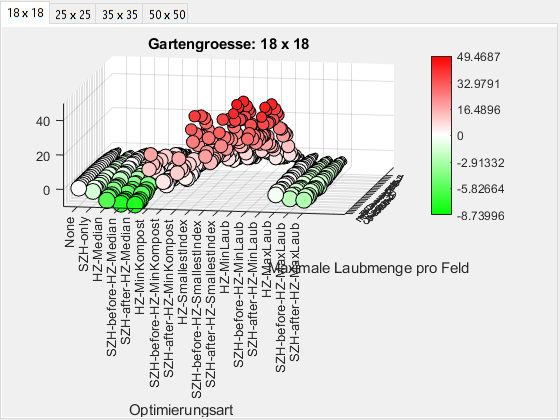

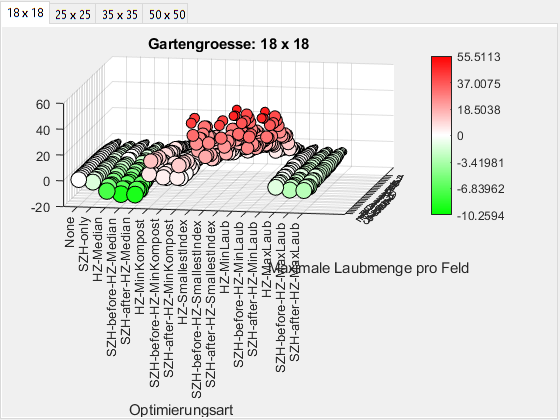

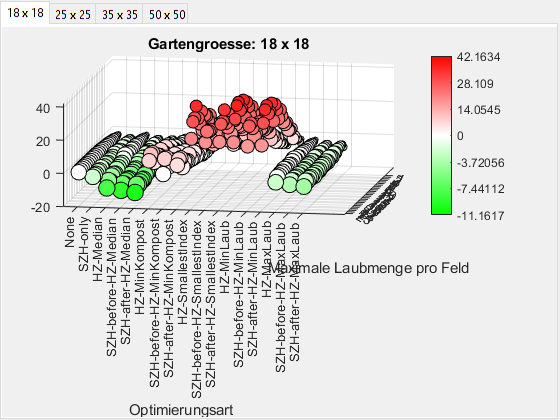

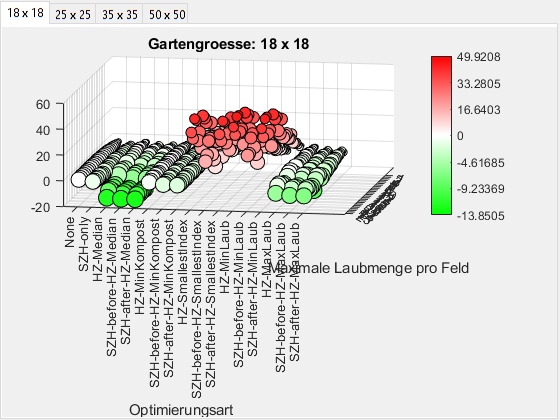

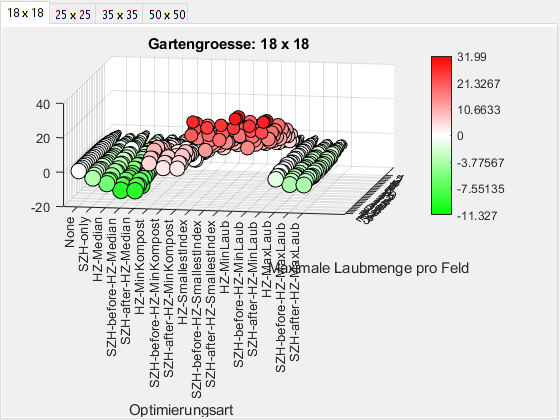

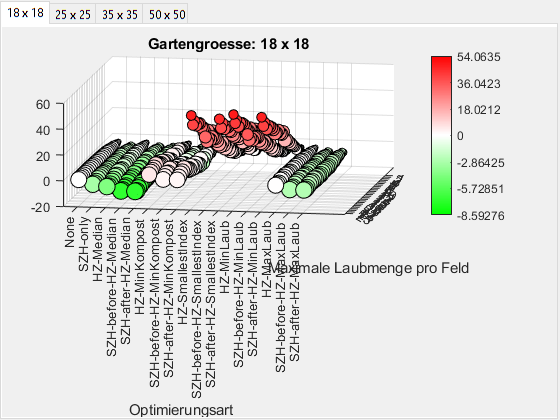

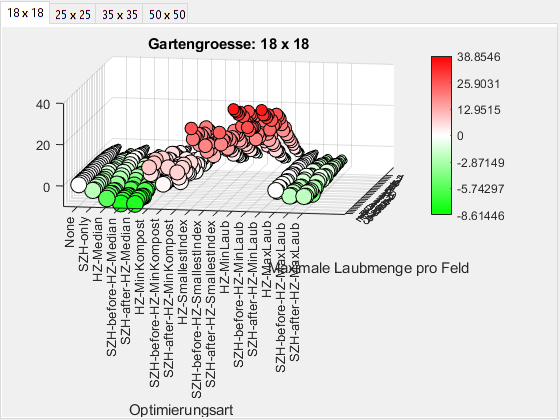

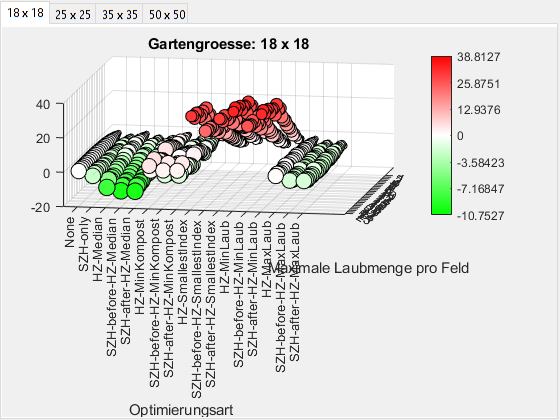

% Nur fuer Batch-Modus:

% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

# Tests für bio-inspirierte Algorithmen

## Szenario 1: Test verschiedener Populationsgroessen beim genetischen Algorithmus

Mit diesem Test soll untersucht werden, wie stark sich die gewählte Populationsgröße auf die Güte der Lösung des genetischen Algorithmus auswirkt.

Dazu wird jeweils ein Garten verschiedener Größen erzeugt, und für diesen Garten mehrere Lösungen mit verschiedenen Populationsgrößen berechnet. Die Ergebnisse werden dann grafisch gegenüber gestellt. Die Tests werden mit den "Standardeinstellungen" der genetischen Parameter durchgeführt. Es wird lediglich die Populationsgröße modifiziert.

if ~testScriptUtils.loadTest(2, 1)
    
    population_sizes = [1, 2, 5, 10, 15, 20, 30, 40, 50];
    
    tm = lhp.utils.TestManager();
    
    for ps = population_sizes
        genparams = lhp.algo.stochastic.genetic.GeneticParameters(...
            "Popsize", ps);
        tm.addAlgorithm(lhp.algo.stochastic.genetic.wrapper(...
            "AlgorithmName", sprintf("Genetisch_Pop%d", ps), ...
            "AlgorithmParams", genparams, ...
            "StoreResults", false, ...
            "StorePopulations", false));
    end
    
    garden_sizes = [10, 15, 20, 30, 50]; %, 100];
    
    for gs = garden_sizes
        G = lhp.Garden.random(gs, gs);
        pdata = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1);
        
        info_str = sprintf("Gartengroesse: %d x %d", gs, gs);
        tm.addTestCase(pdata, info_str);
    end
    
    tm.runAllTests();
    
    % Cleanup variables
    clear("garden_sizes", "population_sizes", "gs", "ps", "pdata", "info_str", "gen_alg");
    
    testScriptUtils.saveTest(2, 1, "tm");
end


Begin running 45 tests!




Test completion: 100.00 %   (   45 /    45)
[==============================================================================]


Wir brauchen keineswegs Zugriff auf die gesamte Lösungstabelle, da wir hier nur mit einem Algorithmus arbeiten. Daher picken wir uns gleich die Daten raus, die uns interessieren. Im speziellen interessieren wir uns für die **Ausführungszeiten**, sowie die **Gesamtkosten** der erzeugten Lösungen.

Wir müssen bei der Auswertung auf jeden Fall beachten, dass wir die Daten jeweils für verschieden-große Gärten aufgenommen haben. Daher sammeln wir zunächst einmal alle verwendeten Gärten in einem Cell-Array. (Die Gärten sind unterschiedlich groß, daher muss das sein)

Mit der Information, welche Gärten es gibt, und basierend auf der Annahme, dass für jeden Garten die selben Populationsgrößen getestet wurden, können wir jetzt die extrahierten Daten umstrukturieren. Wir wählen eine 3D Matrix, in der die Dimensionen die folgenden Bedeutungen haben:

- *1. Dimension (Zeilen)*: Verschiedene Populationsgrößen

- *2. Dimension (Spalten)*: Verschiedene Messungen (aus der Monte-Carlo Simulation)

- *3. Dimension (Tiefe)*: Verschiedene Gärten. Der Index in dieser Dimension ist identisch zum Index der `gardens` Variablen.

algs = tm.get_algorithms(); 
% Preallocate space
stacked_times = nan(numel(algs), 100, size(tm.get_results(), 1));
stacked_scores = stacked_times;
popsizes = zeros(numel(algs), 1);

for a_idx = 1:numel(algs)
    alg = algs{a_idx};
    name = alg.get_name();
    popsizes(a_idx) = double(regexpi(name, "\d+$", "match"));
    NUM_MEAS = alg.NumMonteCarloRuns;
    
    [stacked_times(a_idx, 1:NUM_MEAS, :), ~] = tm.extract(name, "time", "GroupBy", "Garden");
    [stacked_scores(a_idx, 1:NUM_MEAS, :), gardens] = tm.extract(name, "K", "GroupBy", "Garden");
end


Nun da wir die Daten umstrukturiert haben, können wir die Charakteristika extrahieren, die uns tatsächlich interessieren. Da es sich bei den genetischen Algorithmen jeweils um Monte-Carlo Simulationen handelt, betrachten wir statt 10 einzelner Werte pro Garten und Populationsgröße stattdessen die:

- Minima

- Maxima

- Mittelwerte + Standardabweichungen

% Calculate all values we need.
min_scores = min(stacked_scores, [], 2, 'omitnan');
max_scores = max(stacked_scores, [], 2, 'omitnan');
mean_scores = mean(stacked_scores, 2, 'omitnan');
std_scores = std(stacked_scores, [], 2, 'omitnan');

mean_times = mean(stacked_times, 2, 'omitnan');
std_times = std(stacked_times, [], 2, 'omitnan');


Zu guter letzt werden die Daten grafisch dargestellt.

**Beobachtungen und Interpretation der Ergebnisse**:

- Die Rechenzeit steigt linear mit der Populationsgröße an

- Ab einer Gartengröße von 15x15 Feldern ist kaum eine weitere Verbesserung der Ergebnisse beobachtbar, wenn die Populationsgröße über 15 hinaus erhöht wird. Die Population scheint in diesen Fällen vorzeitig zu konvergieren.

- Ab einer Populationsgröße von 15 ist die Standardabweichung der Gesamtkosten über 10 erzeugte Lösungen kleiner als 2 % des Mittelwerts der Gesamtkosten. In anderen Worten scheint die Lösung des Algorithmus ebenfalls zu konvergieren.

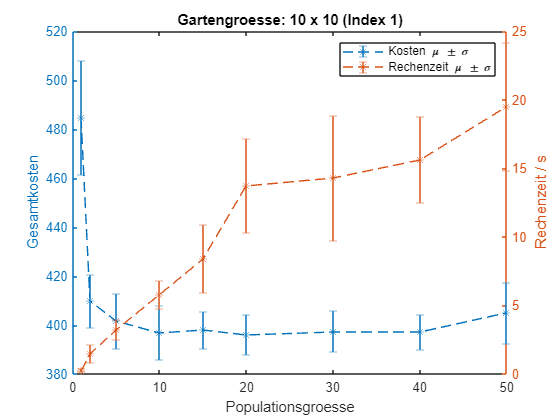

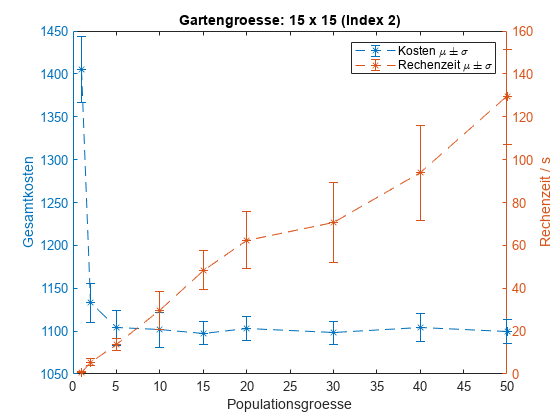

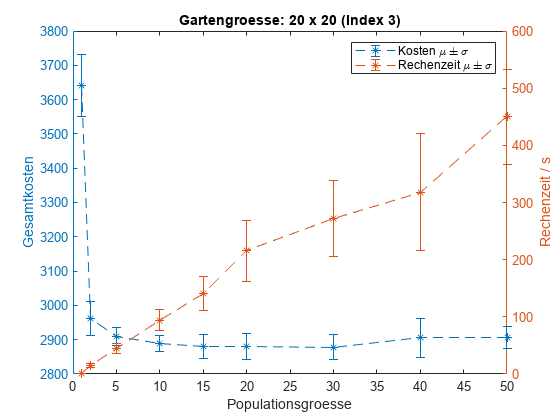

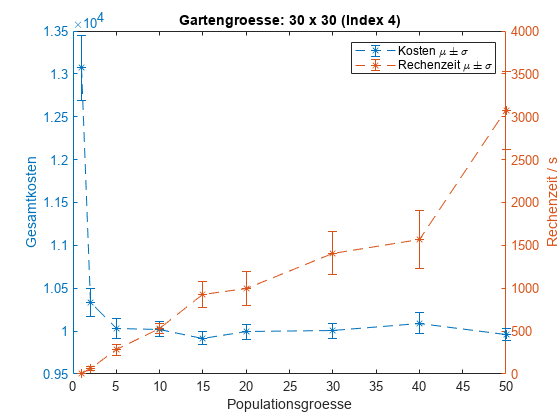

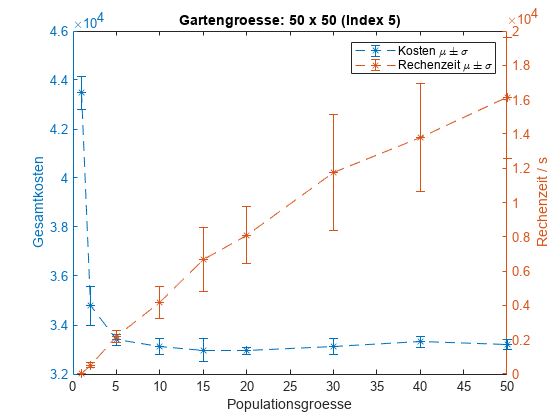

for garden_idx = 1:numel(gardens)
    figure();
    gca();
    title(sprintf("Gartengroesse: %d x %d (Index %d)", size(gardens{garden_idx}), garden_idx));
    xlabel("Populationsgroesse");
    
    % Plot the Scores first
    yyaxis("left");
%     plot(population_sizes, min_scores(:, :, garden_idx), "--*", "DisplayName", "Minimum");
%     plot(population_sizes, max_scores(:, :, garden_idx), "--*", "DisplayName", "Maximum");
    plt = errorbar(popsizes, mean_scores(:, :, garden_idx), std_scores(:, :, garden_idx), ...
        "--*", "DisplayName", "Kosten \mu \pm \sigma");
    plt.DataTipTemplate.DataTipRows(1).Label = "Populationsgroesse";
    plt.DataTipTemplate.DataTipRows(2).Label = "Rechenzeit in Sekunden";
    ylabel("Gesamtkosten");
    legend();
    % Change y-axis to log style
%     ax.YScale = "log";
    
    % Then plot the times
    yyaxis("right");
%     plot(population_sizes, min_times(:, :, garden_idx), "--*", "DisplayName", "Minimum");
%     plot(population_sizes, max_times(:, :, garden_idx), "--*", "DisplayName", "Maximum");
    plt = errorbar(popsizes, mean_times(:, :, garden_idx), std_times(:, :, garden_idx), ...
        "--*", "DisplayName", "Rechenzeit \mu \pm \sigma");
    plt.DataTipTemplate.DataTipRows(1).Label = "Populationsgroesse";
    plt.DataTipTemplate.DataTipRows(2).Label = "Rechenzeit in Sekunden";
    ylabel("Rechenzeit / s");
    legend();
    % Change y-axis to log style
%     ax.YScale = "log";
    

end


% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

## Szenario 2: Unterschied zwischen strikter und nicht-strikter Bewertung (genetic)

Der genetische Algorithmus unterscheidet intern 2 Arten, die Gesamtkosten einer Lösung zu betrachten: Mit strikter und nicht strikter Bewertung. Bei der strikten Bewertung werden alle 3 Kostenposten (Harkaufwand, Transportarbeit und Unproduktive Wege) exakt berechnet, bei der nicht strikten Bewertung werden die unproduktiven Wege vernachlässigt.

Dieser Test ist aus algorithmischer Perspektive interessant, da der genetische Algorithmus interne Datenstrukture verwaltet, aus denen sich die ersten beiden Kostenposten direkt berechnen lassen. Bei der Ermittlung der unproduktiven Wege muss hingegen über alle Quellknoten einer Lösung iteriert werden, was Zeitaufwendig ist. Aus Sicht der entstehenden Gesamtkosten ist dieser Aufwand fragwürdig, da die unproduktiven Wege in der Regel einen kleinen Anteil an den Gesamtkosten haben.

Dieser Test soll untersuchen, ob eine Berücksichtigung der unproduktiven Wege bei der Algorithmen-internen Ermittlung der Gesamtkosten die erzielten Ergebnisse signifikant beeinflusst. **Beachte**: Bei der finalen Bewertung der Ergebnisse (die in den folgenden Plots erscheinen) werden alle Kosten berechnet!

if ~testScriptUtils.loadTest(2, 2)
    
    
    tm = lhp.utils.TestManager();
    
    genparam_strict = lhp.algo.stochastic.genetic.GeneticParameters("Strict", true);
    genparam_nonstrict = lhp.algo.stochastic.genetic.GeneticParameters("Strict", false);
    
    tm.addAlgorithm(lhp.algo.stochastic.genetic.wrapper(...
        "StoreResults", false, ...
        "StorePopulations", false, ...
        "AlgorithmParams", genparam_strict, ...
        "AlgorithmName", "Genetisch_strict"));
    tm.addAlgorithm(lhp.algo.stochastic.genetic.wrapper(...
        "StoreResults", false, ...
        "StorePopulations", false, ...
        "AlgorithmParams", genparam_nonstrict, ...
        "AlgorithmName", "Genetisch_nonstrict"));
    
    garden_sizes = [10, 15, 20, 25, 30];
    
    for gs = garden_sizes
        G = lhp.Garden.random(gs, gs);
        pdata = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1);
        
        info_str = sprintf("Gartengroesse: %d x %d", gs, gs);
        tm.addTestCase(pdata, info_str);
    end
    
    tm.runAllTests();
    
    % Cleanup variables
    clear("gen_alg", "garden_sizes", "strict_values", "gs", "G", "pdata", "sv", "info_str");
    
    testScriptUtils.saveTest(2, 2, "tm");
end


Begin running 10 tests!

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).



Test completion: 100.00 %   (   10 /    10)
[==============================================================================]


**Beobachtungen und Interpretation der Ergebnisse**:

- Bis zu einer Gartengröße von 25x25 Feldern liefert die nicht strikte Bewertung im Mittel bessere Ergebnisse als die strikte Bewertung

- Bei der Gartengröße von 30x30 Feldern kehrt sich dieser Effekt um. Eine mögliche Ursache für dieses Verhalten könnte die Tatsache sein, dass in größeren Gärten tendenziell öfter unproduktive Wege zwischen einzelnen Hubs zurück gelegt werden müssen.

- Abhängig von der Gartengröße bringt die nicht strikte Bewertung im Mittel eine Zeitersparnis von 20 % (10x10 Felder) bis 80 % (30x30 Felder) gegenüber der strikten Bewertung

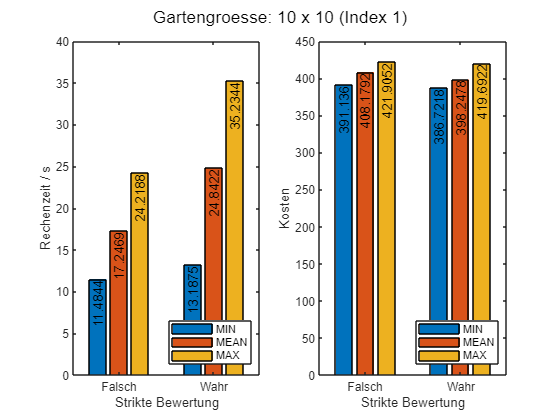

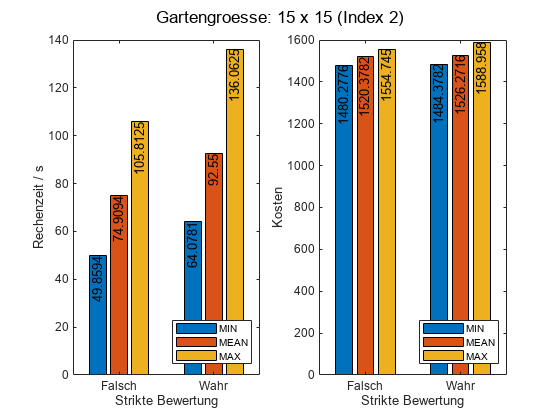

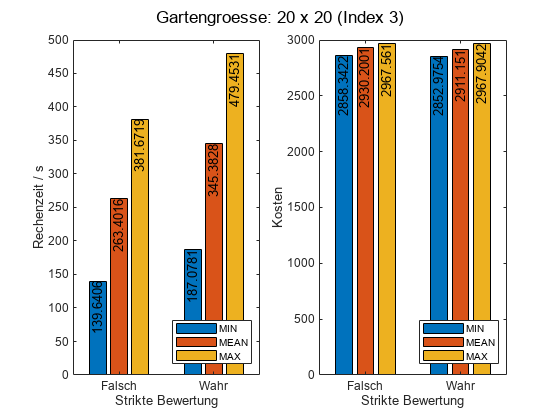

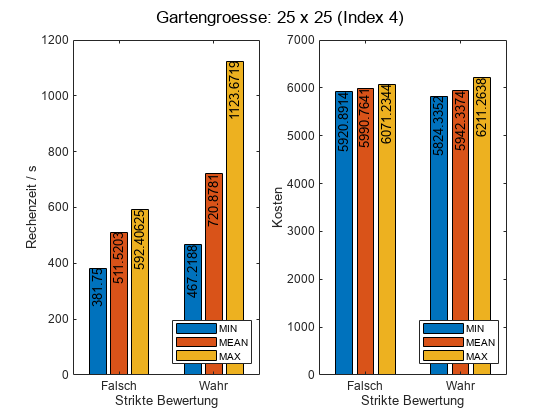

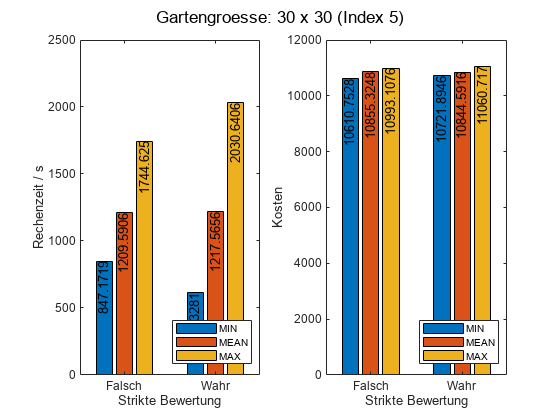

stacked_scores = [...
    tm.extract("Genetisch_nonstrict", "K", "GroupBy", "Garden"); ...
    tm.extract("Genetisch_strict", "K", "GroupBy", "Garden")];
stacked_times = [...
    tm.extract("Genetisch_nonstrict", "time", "GroupBy", "Garden");
    tm.extract("Genetisch_strict", "time", "GroupBy", "Garden")];
tmp = [tm.get_results().ProblemData{:}];
gardens = {tmp.Garden};
stricts = [0, 1];

for idx = 1:numel(gardens)
    figure();
    subplot(1, 2, 1);
    times_min_mean_max = [...
        min(stacked_times(:, :, idx), [], 2), ...
        mean(stacked_times(:, :, idx), 2), ...
        max(stacked_times(:, :, idx), [], 2)];
    b = bar(stricts, times_min_mean_max);
    xlabel("Strikte Bewertung");
    xticklabels(["Falsch", "Wahr"]);
    ylabel("Rechenzeit / s");
    legend(["MIN", "MEAN", "MAX"], "Location", "southeast");
    % Customize bars and add numeric values, too
    for i = 1:size(times_min_mean_max, 2)
        xtips = b(i).XEndPoints;
        ytips = b(i).YEndPoints;
        labels = string(b(i).YData);
        t = text(xtips, ytips, labels, ...
            "HorizontalAlignment", "right", ...
            "VerticalAlignment", "middle", ...
            "Rotation", 90);
    end
    
    subplot(1, 2, 2);
    scores_min_mean_max = [...
        min(stacked_scores(:, :, idx), [], 2), ...
        mean(stacked_scores(:, :, idx), 2), ...
        max(stacked_scores(:, :, idx), [], 2)];
    b = bar(stricts, scores_min_mean_max);
    xlabel("Strikte Bewertung");
    xticklabels(["Falsch", "Wahr"]);
    ylabel("Kosten");
    legend(["MIN", "MEAN", "MAX"], "Location", "southeast");
    % Customize bars and add numeric values, too
    for i = 1:size(times_min_mean_max, 2)
        xtips = b(i).XEndPoints;
        ytips = b(i).YEndPoints;
        labels = string(b(i).YData);
        t = text(xtips, ytips, labels, ...
            "HorizontalAlignment", "right", ...
            "VerticalAlignment", "middle", ...
            "Rotation", 90);
    end
    
    sgtitle(sprintf("Gartengroesse: %d x %d (Index %d)", size(gardens{idx}), idx));
end


% ALTERNATIVE DARSTELLUNG: LINIENPLOT UEBER GARTENGROESSE AUF X ACHSE!

% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

## Szenario 3: Lösungsgüte des Bienenalgorithmus abhängig von MaxIter

In diesem Test soll untersucht werden, welche Verbesserung eine Vergrößerung des Parameters "MaxIter" beim Bienenalgorithmus tatsächlich bewirken kann. Dazu werden 5 Gärten verschiedener Größen generiert und in jedem dieser Gärten der Bienenalgorithmus in einer Monte-Carlo Simulation mit 5 Durchläufen ausgeführt. Darüber hinaus wird der Parameter "MaxIter" mit den Werten 10, 20, 50, 100, 200 und 500 gewählt.

Am Ende wird dargestellt, wie sich die erzielten Gesamtkosten neben der Ausführungszeit mit den o.g. Parametern entwickeln.

Die Durchführung aller genannten Tests dauert (Stand: 15.02.2021) mehr als 36 Stunden. Aus diesem Grund ist eine Datei mit berechneten Ergebnissen vorhanden ("Test-2-3_*.mat"), die in der nächsten Sektion eingelesen werden kann. Dort ist eine Instanz des TestManager enthalten mit den Werten, die bei der ursprünglichen Evaluierung berechnet wurden.

if ~testScriptUtils.loadTest(2, 3)
    
    tm = lhp.utils.TestManager();
    
    %% Define the tests.
    % Define garden sizes
    garden_sizes = [10, 15, 20, 30, 50];
    % Define bee algorithm iterations
    bee_iters = [10, 20, 50, 100, 200];
    
    for bi = bee_iters
        beep = lhp.algo.stochastic.bee.BeeParameters(...
            "MaxIter", bi);
        algo = lhp.algo.stochastic.bee.wrapper(...
            "AlgorithmParams", beep, ...
            "AlgorithmName", sprintf("Bienen_%d", bi));
        tm.addAlgorithm(algo);
    end
    
    % Stelle sicher, dass wir immer die selben Gaerten verwenden!
    for gs = garden_sizes
        G = lhp.Garden.random(gs, gs);
        data = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1, ...
            "MaxLaub", 20, ...
            "MaxLade", 20);
        
        info_str = sprintf("Garden: %d x %d", gs, gs);
        tm.addTestCase(data, info_str);
    end
        
    %% Run the tests
    tm.runAllTests();
    
    testScriptUtils.saveTest(2, 3, "tm", "bee_iters");
end


Begin running 25 tests!

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).



Test completion: 100.00 %   (   25 /    25)
[==============================================================================]


**Beobachtungen und Interpretation der Testergebnisse.**

Wir stellen die Kosten und die Ausführungszeiten getrennt dar. Es ist klar erkenntlich, dass eine Vergrößerung des Parameters "MaxIter" die Kosten marginal senkt, während die Rechenzeit exponentiell wächst.

- Die beste erzielte Kostenersparnis (7 %) gegenüber "MaxIter = 10" wurde bei Gärten der Größe 10x10 Feldern mit 100 Iterationen erzielt. Der Zeitbedarf war dafür um einen Faktor 6.9 größer.

- Eine Erhöhung des Parameter MaxIter um den Faktor $n$ geht mit einer Erhöhung der Rechenzeit um einen Faktor von ca. $n \cdot \frac{2}{3}$ einher.

- Die Kostenersparnis durch den Bienenalgorithmus stehen, insbesondere für große Gärten, kaum im Verhältnis zum zusätzlichen Zeitaufwand.

## Im gespeicherten Testset

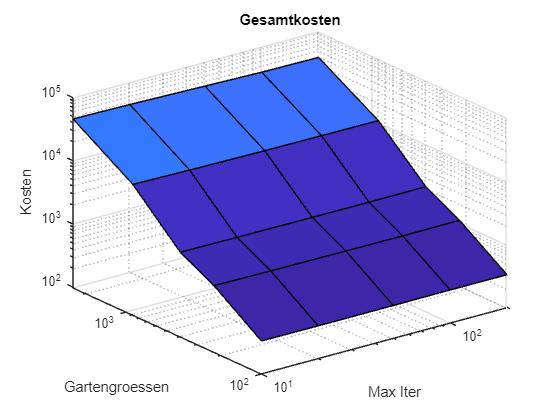

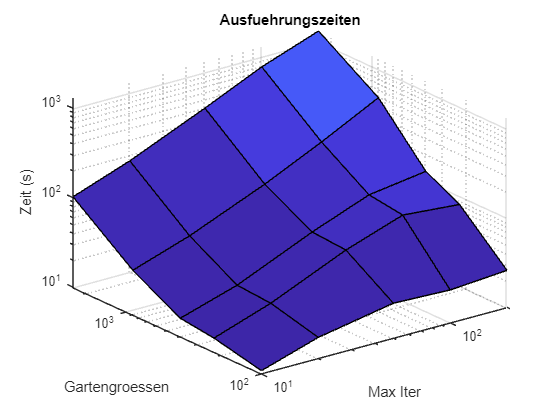

costs = [];
times = [];
% gardens = cell.empty(numel(bee_iters), 0);

for iter = bee_iters
    [c, g] = tm.extract(sprintf("Bienen_%d", iter), "K", ...
        "GroupBy", "Garden");
    costs = cat(1, costs, c);
    
    t = tm.extract(sprintf("Bienen_%d", iter), "time", ...
        "GroupBy", "Garden");
    times = cat(1, times, t); 
end

gardens = g;

mean_costs = mean(costs, 2);
mean_times = mean(times, 2);
X = bee_iters;
Y = cellfun(@(cell) (numel(cell)), gardens);
% Dim 1: gardens
% Dim 2: Max Iter
% Dim 3: (1)
Z_costs = permute(mean_costs, [3, 1, 2]);
Z_times = permute(mean_times, [3, 1, 2]);

titles = ["Gesamtkosten", "Ausfuehrungszeiten"];
zlabels = ["Kosten", "Zeit (s)"];
datas = {Z_costs, Z_times};

for plotidx = 1:2
    figure();
    surf(X, Y, datas{plotidx});
    % X-Achse
    xlabel("Max Iter");
%     xticks(1:numel(X));
%     xticklabels(X);
    % Y-Achse
    ylabel("Gartengroessen");
%     yticks(1:numel(Y));
%     yticklabels(Y);
    % Restliche Formatierung
    title(titles(plotidx));
    zlabel(zlabels(plotidx));
    grid("minor");
    ax = gca();
    ax.XScale = 'log';
    ax.YScale = 'log';
    ax.ZScale = 'log';
end

% Relative cost reduction and time increase

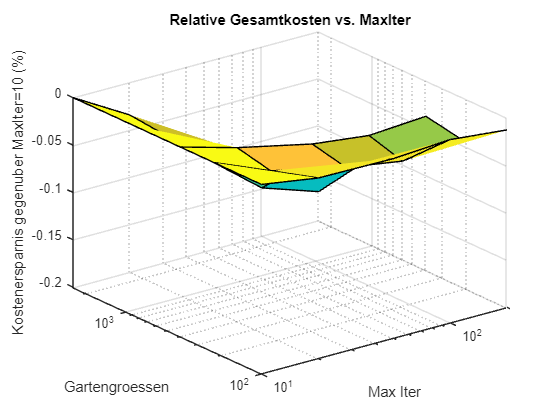

mean_costs = squeeze(mean_costs);
mean_times = squeeze(mean_times);
rel_costs = (mean_costs(1:end, :) - mean_costs(1, :)) ./ mean_costs(1, :);
rel_times = (mean_times(1:end, :) - mean_times(1, :)) ./ mean_times(1, :);

figure();
surf(X, Y, rel_costs');
title("Relative Gesamtkosten vs. MaxIter");
xlabel("Max Iter");
ylabel("Gartengroessen");
zlabel(sprintf("Kostenersparnis gegenuber MaxIter=%d (%%)", X(1)));
ax = gca();
ax.XScale = 'log';
ax.YScale = 'log';

figure();

surf(X, Y, rel_times');
title("Relative Ausfuehrungsdauer vs. MaxIter");
xlabel("Max Iter");
ylabel("Gartengroessen");
zlabel(sprintf("Zeitbedarf gegenuber MaxIter=%d (%%)", X(1)));
ax = gca();
ax.XScale = 'log';
ax.YScale = 'log';

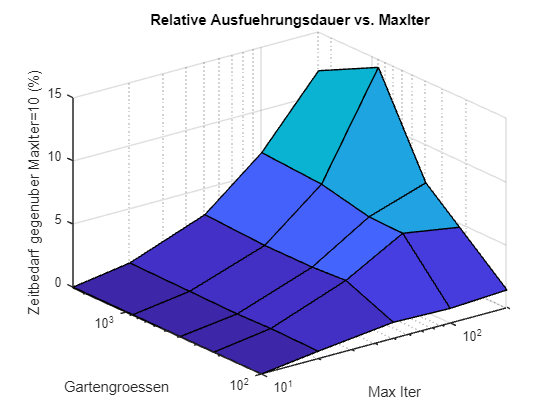

% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um

% Doppeldeutigkeiten zu vermeiden.
clearvars;

# Gemischte Testszenarien

## Genetischer Algorithmus gegen Laubmengenoptimierte Heuristiken mit und Ohne Aufwänden nach CPA

In dieser Testreihe soll untersucht werden, wie sich die Algorithmen verhalten wenn die Arbeitsaufwände nach dem **Compendium of Physical Activities** (CPA) ermittelt werden.

Dazu verwenden wir die folgenden Kostenfaktoren:

- Wegeparameter: 1.2

- Transportparameter: 1.4

- Harkparameter: 1.0

Entsprechend der folgenden Einträge aus dem CPA:

Die Idee hinter diesem Test ist, dass die Heuristiken, unabhängig von den einzelnen Kostenkoeffizienten, stets die selben Lösungen erzeugen. In solchen Fällen, wo das Harken im Vergleich zum Transport sehr teuer ist, kann eine derart ermittelte Lösung suboptimal ausfallen. Demgegenüber optimiert der genetische Algorithmus die Lösungen der Population hinsichtlich der erreichten Fitness, und berücksichtigt damit auch die Kostenparameter.

Im Idealfall soll beobachtet werden, dass die Kosten der Heuristiken aufgrund der mangelnden Anpassungsfähigkeit sehr hoch ausfallen, während der genetische Algorithmus nach wie vor optimale Lösungen erzeugt. Um den Heuristiken ein Stück weit entgegen zu kommen, wird die Laubmengenoptimierung aktiviert.

if ~testScriptUtils.loadTest(3, 1)
    
    import('lhp.algo.DeterministicWrapper');

    % Definition der zu testenden Algorithmen
    algorithms_to_test = DeterministicWrapper.gather("Range", [13, 61, 12, 7], "OptimizeMaxLaub", true);
    genetic = lhp.algo.stochastic.genetic.wrapper("StoreResults", false, "StorePopulations", false);
    bee = lhp.algo.stochastic.bee.wrapper("StoreResults", false, "StorePopulations", false);
    
    tm = lhp.utils.TestManager();
    for att = algorithms_to_test
        tm.addAlgorithm(att);
    end
    tm.addAlgorithm(genetic);
    tm.addAlgorithm(bee);
    
    garden_sizes = [10, 15, 20, 25, 30];
    % Harken, Wege, Transport
    work_factors = [1.0, 1.0, 1.0; ...
                    1.0, 1.2, 1.4];
    
    for gs = garden_sizes
        G = lhp.Garden.random(gs, gs);
        pdata = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1, ...
            "MaxLaub", 20, ...
            "MaxLade", 20);
        
        for wf = 1:size(work_factors, 1)
            pdata.Rake_Param = work_factors(wf, 1);
            pdata.Unprod_Param = work_factors(wf, 2);
            pdata.Trans_Param = work_factors(wf, 3);
            info_str = sprintf("Gartengroesse: %d x %d; Hark, Wege, Transport Param: %d, %d, %d", ...
                gs, gs, work_factors(wf, 1), work_factors(wf, 2), work_factors(wf, 3));
            tm.addTestCase(pdata, info_str);
        end
    end
    
    tm.runAllTests();
    
    % Cleanup variables
    clear("garden_sizes", "work_factors", "gs", "G", "pdata", "wf", "info_str");
    
    testScriptUtils.saveTest(3, 1, "tm", "algorithms_to_test");
end


Begin running 60 tests!

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).



Test completion: 100.00 %   (   60 /    60)
[==============================================================================]


**Beobachtungen und Interpretation der Ergebnisse**:

- Der genetische Algorithmus ist in den Tests ohne CPA in 3 Fällen dem Cluster-MAX unterlegen. In den Testfällen nach CPA ist er dem Cluster-MAX in 4 Fällen unterlegen.

- Die Kosten der Lösungen aller Algorithmen bei Verwendung der Aufwandsparameter nach CPA erhöhen sich im Schnitt um 15 - 20 %.

- Eine Überlegenheit des genetischen Algorithmus gegenüber den laubmengenoptimierten Heuristiken ist nicht feststellbar.

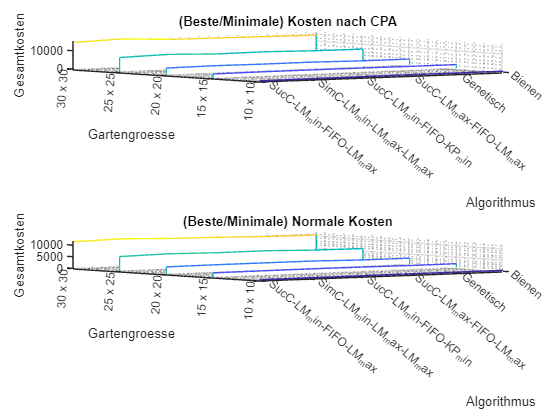

costs = [];
times = [];
alg_names = [];

algorithms_to_test = tm.get_algorithms();

for alg_idx = 1:numel(algorithms_to_test)
    alg = algorithms_to_test{alg_idx}   ;
    alg_name = alg.get_name();
    alg_names = [alg_names; alg_name]; %#ok
    stacked_scores = tm.extract(alg_name, "K", "GroupBy", "Garden", "SortBy", "Unprod_Param");
    [stacked_times, gardens, params] = tm.extract(...
        alg_name, "time", "GroupBy", "Garden", "SortBy", "Unprod_Param");
    is_cpa = params > 1.1;
    not_cpa = ~is_cpa;
    costs(alg_idx, :, is_cpa) = min(stacked_scores(is_cpa, :, :), [], 2);   %#ok
    costs(alg_idx, :, not_cpa) = min(stacked_scores(not_cpa, :, :), [], 2); %#ok
    times(alg_idx, :, is_cpa) = mean(stacked_times(is_cpa, :, :), 2);       %#ok
    times(alg_idx, :, not_cpa) = mean(stacked_times(not_cpa, :, :), 2);     %#ok
end
    
% Kosten
figure();
subplot(2, 1, 1);
waterfall(costs(:, :, is_cpa)');
title("(Beste/Minimale) Kosten nach CPA");
grid("minor");
xlabel("Algorithmus");
xticklabels(alg_names);
xtickangle(-40);
ylabel("Gartengroesse");
yticklabels(cellfun(@(cell) sprintf("%d x %d", size(cell, 1), size(cell, 2)), gardens));
zlabel("Gesamtkosten");
subplot(2, 1, 2);
waterfall(costs(:, :, not_cpa)');
title("(Beste/Minimale) Normale Kosten");
grid("minor");
xlabel("Algorithmus");
xticklabels(alg_names);
xtickangle(-40);
ylabel("Gartengroesse");
yticklabels(cellfun(@(cell) sprintf("%d x %d", size(cell, 1), size(cell, 2)), gardens));
zlabel("Gesamtkosten");
    

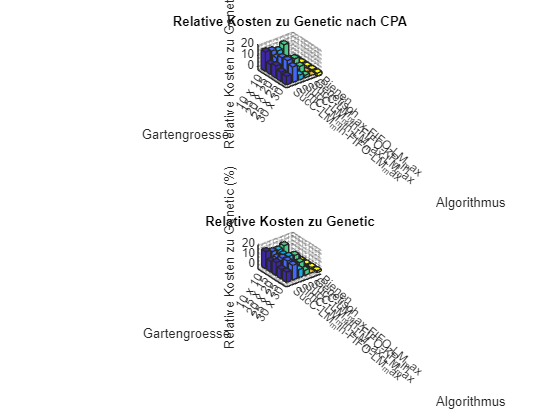

% Relative Kosten
% In Relation zu den Kosten, die der genetische Algorithmus erzeugt.
rel_costs = (costs(1:end, :, :) - costs(end-1, :, :)) ./ (costs(end-1, :, :)) * 100;

figure();
subplot(2, 1, 1);
bar3(rel_costs(:, :, is_cpa)');
title("Relative Kosten zu Genetic nach CPA");
grid("minor");
xlabel("Algorithmus");
xticklabels(alg_names);
xtickangle(-40);
ylabel("Gartengroesse");
yticklabels(cellfun(@(cell) sprintf("%d x %d", size(cell, 1), size(cell, 2)), gardens));
zlabel("Relative Kosten zu Genetic (%)");
subplot(2, 1, 2);
bar3(rel_costs(:, :, not_cpa)');
title("Relative Kosten zu Genetic");
grid("minor");
xlabel("Algorithmus");
xticklabels(alg_names);
xtickangle(-40);
ylabel("Gartengroesse");
yticklabels(cellfun(@(cell) sprintf("%d x %d", size(cell, 1), size(cell, 2)), gardens));
zlabel("Relative Kosten zu Genetic (%)");


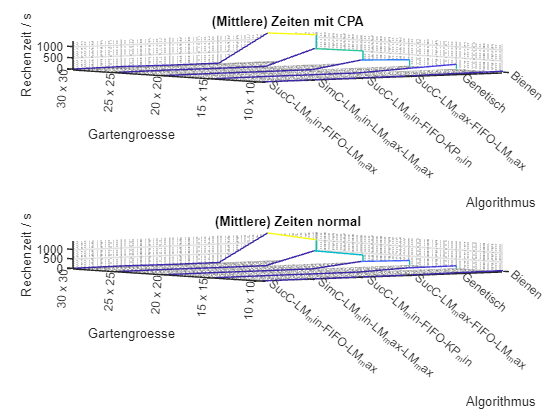

% Zeiten
figure();
subplot(2, 1, 1);
waterfall(times(:, :, is_cpa)');
title("(Mittlere) Zeiten mit CPA");
grid("minor");
xlabel("Algorithmus");
xticklabels(alg_names);
xtickangle(-40);
ylabel("Gartengroesse");
yticklabels(cellfun(@(cell) sprintf("%d x %d", size(cell, 1), size(cell, 2)), gardens));
zlabel("Rechenzeit / s");
subplot(2, 1, 2);
waterfall(times(:, :, not_cpa)');
title("(Mittlere) Zeiten normal");
grid("minor");
xlabel("Algorithmus");
xticklabels(alg_names);
xtickangle(-40);
ylabel("Gartengroesse");
yticklabels(cellfun(@(cell) sprintf("%d x %d", size(cell, 1), size(cell, 2)), gardens));
zlabel("Rechenzeit / s");


% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.
clearvars;

## Wettkampf-Testset: Alle Algorithmen gegen einander

if ~testScriptUtils.loadTest(3, 2)
    import('lhp.algo.*');
    
    % Waehle die besten Heuristiken
    heuristics = DeterministicWrapper.gather(...
        "StoreResults", false, ...
        "OptimizeMaxLaub", true, ...
        "Range", [16, 19, 12, 7, 29, 49, 41, 45, 61, 77, 81]);
    genetic = lhp.algo.stochastic.genetic.wrapper(...
        "StoreResults", false, ...
        "StorePopulations", false);
    bienen = lhp.algo.stochastic.bee.wrapper(...
        "StoreResults", false);
    
    tm = lhp.utils.TestManager();
    for heur = heuristics
        tm.addAlgorithm(heur);
    end
    tm.addAlgorithm(genetic);
    tm.addAlgorithm(bienen);
    
    garden_sizes = [15, 20, 25, 30, 50];
    
    for gs = garden_sizes
        G = lhp.Garden.random(gs, gs);
        pdata = lhp.ProblemData(gs, gs, ...
            "Garten", G, ...
            "HarkParam", 1, ...
            "WegeParam", 1, ...
            "TransParam", 1, ...
            "MaxLaub", 20, ...
            "MaxLade", 20);
        
        info_str = sprintf("Gartengroesse: %d x %d", gs, gs);
        tm.addTestCase(pdata, info_str);
    end
    
    tm.runAllTests();
    
    testScriptUtils.saveTest(3, 2, "tm", "garden_sizes");
end


results = tm.get_results();
alg_name_cells = results.Properties.VariableNames(4:end);

Begin running 65 tests!




Test completion: 100.00 %   (   65 /    65)
[==============================================================================]


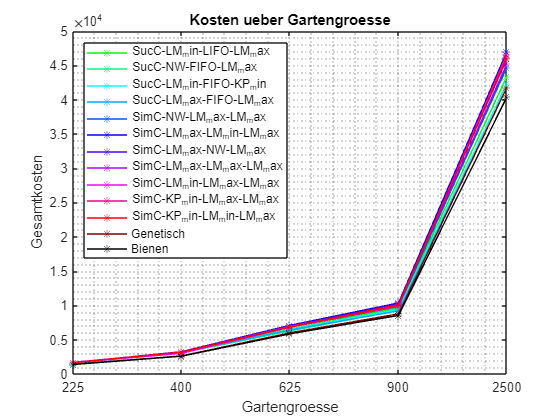

alg_names = [cellfun(@(cell) string(cell), alg_name_cells)]; %#ok

f_costs = figure();
f_times = figure();

cost_mat = zeros(size(results(:, 4:end)));
time_mat = zeros(size(results(:, 4:end)));
garden_sizes = [15, 20, 25, 30, 50, 70].^2;

for an_idx = 1:numel(alg_names)
    costs = tm.extract(alg_names(an_idx), "K", ...
        "GroupBy", "Garden");
    times = tm.extract(alg_names(an_idx), "time", ...
        "GroupBy", "Garden");
    
    cost_mat(1:size(costs, 3), an_idx) = permute(mean(costs, 2), [3 1 2]);
    time_mat(1:size(costs, 3), an_idx) = permute(mean(times, 2), [3 1 2])';
end

plot_colors = varycolor(numel(alg_names));

figure();
for tmp = 1:numel(alg_names)
    plot(cost_mat(:, tmp), "-*", "Color", plot_colors(tmp, :));
    hold on;
end
legend(alg_names, "Location", "northwest");
grid("minor");
xlabel("Gartengroesse");
xticks(1:numel(garden_sizes));
xticklabels(garden_sizes);
ylabel("Gesamtkosten");
title("Kosten ueber Gartengroesse");

figure();
for tmp = 1:numel(alg_names)
    semilogy(time_mat(:, tmp), "-*", "Color", plot_colors(tmp, :));

    hold on;
end
% semilogy(time_mat);
legend(alg_names, "Location", "northwest");
grid("minor");
xlabel("Gartengroesse");
xticks(1:numel(garden_sizes));
xticklabels(garden_sizes);
ylabel("Ausfuehrungsdauer (s)");
title("Ausfuehrungsdauer ueber Gartengroesse");


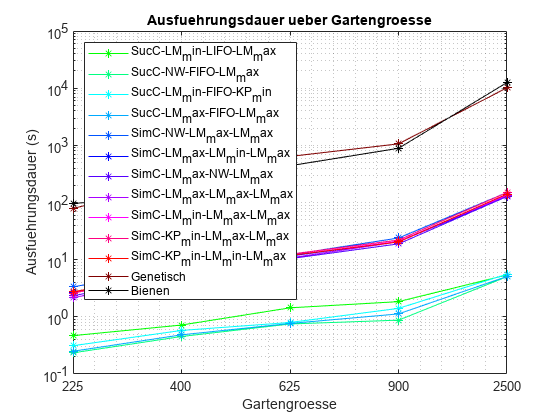

% Nur fuer Batch-Modus:
% Loesche alle Workspace-Variablen bevor wir weiter gehen, um
% Doppeldeutigkeiten zu vermeiden.

clearvars;
